# Dummy contrasts of stim

Model (CESO)

parameter:

- `C``ue: onset01_cue`

- `E``xpect rating:ul onset02_ratingexpect, pmod_expectRT`

- `S``timulus: onset03_stimulus`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

## Pain > baseline

#### Pain > baseline :: load dataset

contrast_of_interest = 'simple_stim_P';

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel';
nifti_save_fname_prefix = 'model02-CESO_epoch-stim';

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';
contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 37938060 bytes
Loading image number:    95
Elapsed time is 121.427241 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9025366  Bit rate: 23.11 bits


#### Pain > baseline :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:24:52 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain > baseline :: Plot diagnostics, before l2norm

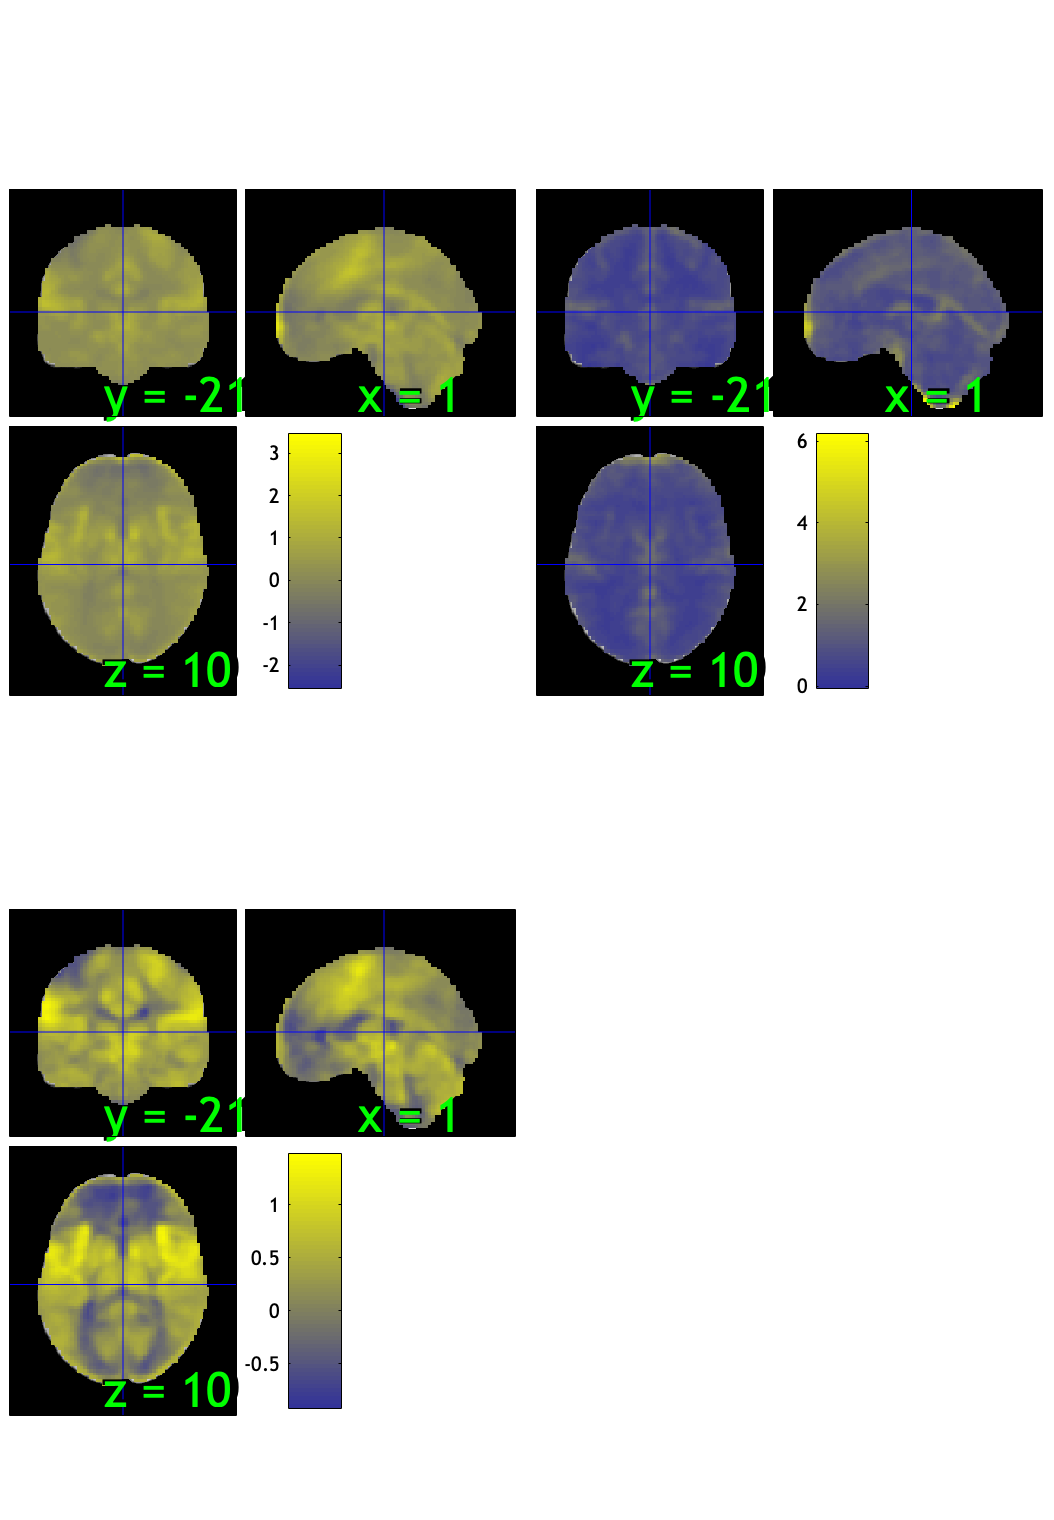

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 24.21%
Expected 4.75 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 9 23 24 
Uncorrected: 9 images		Cases 5 9 11 23 24 25 67 71 79 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.42%
Expected 4.75 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 12 59 64 66 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                    

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:25:38 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

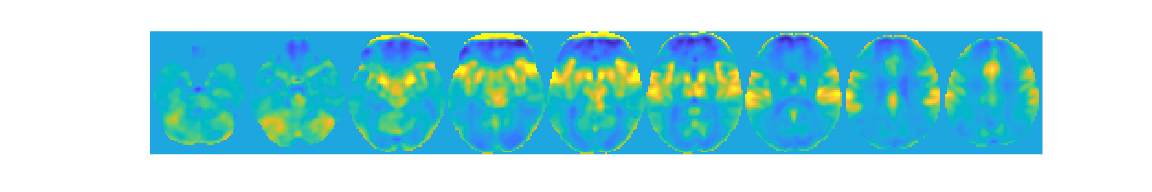

wh_outlier_uncorr = 95×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   1
   0


wh_outlier_corr = 95×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Pain > baseline :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Pain > baseline :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 95


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×91 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [91×21 char]
              fullpath: [95×112 char]
           files_exist: [95×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×91 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [91×21 char]
              fullpath: [91×112 char]
           files_exist: [95×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×91 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [91×21 char]
              fullpath: [91×112 char]
           files_exist: [91×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 4 participants, size is now 91


#### Pain > baseline :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain > baseline :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


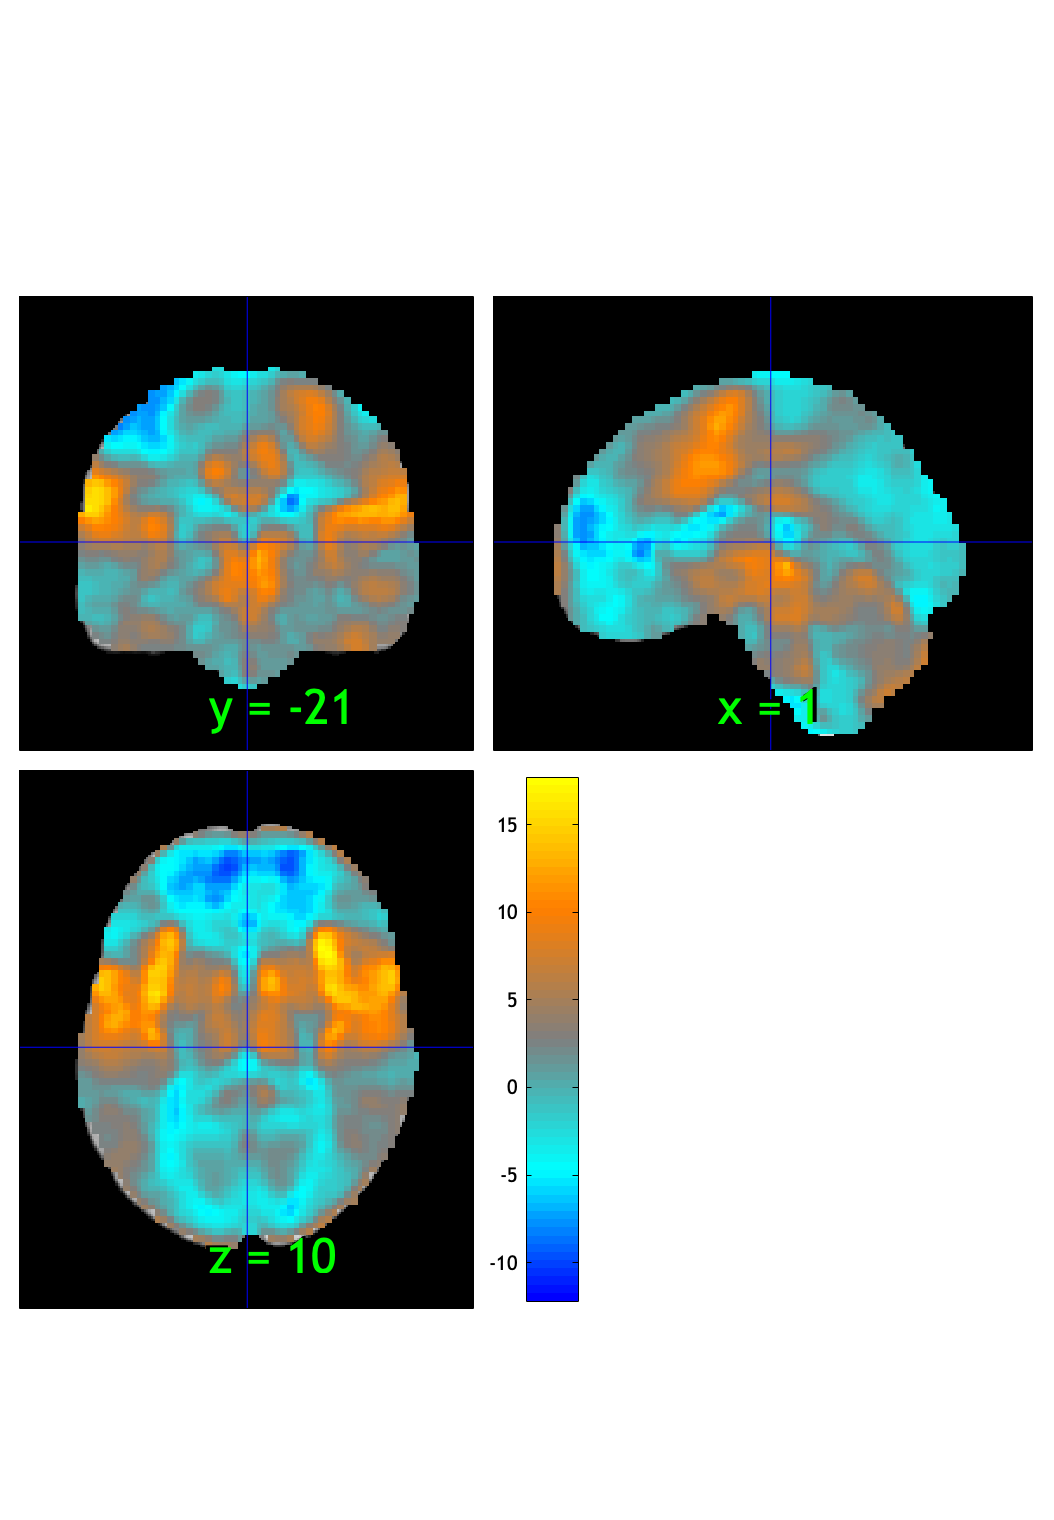

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:25:51 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.026048

Image   1
 42 contig. clusters, sizes   1 to 51636
Positive effect: 34773 voxels, min p-value: 0.00000000
Negative effect: 17247 voxels, min p-value: 0.00000000


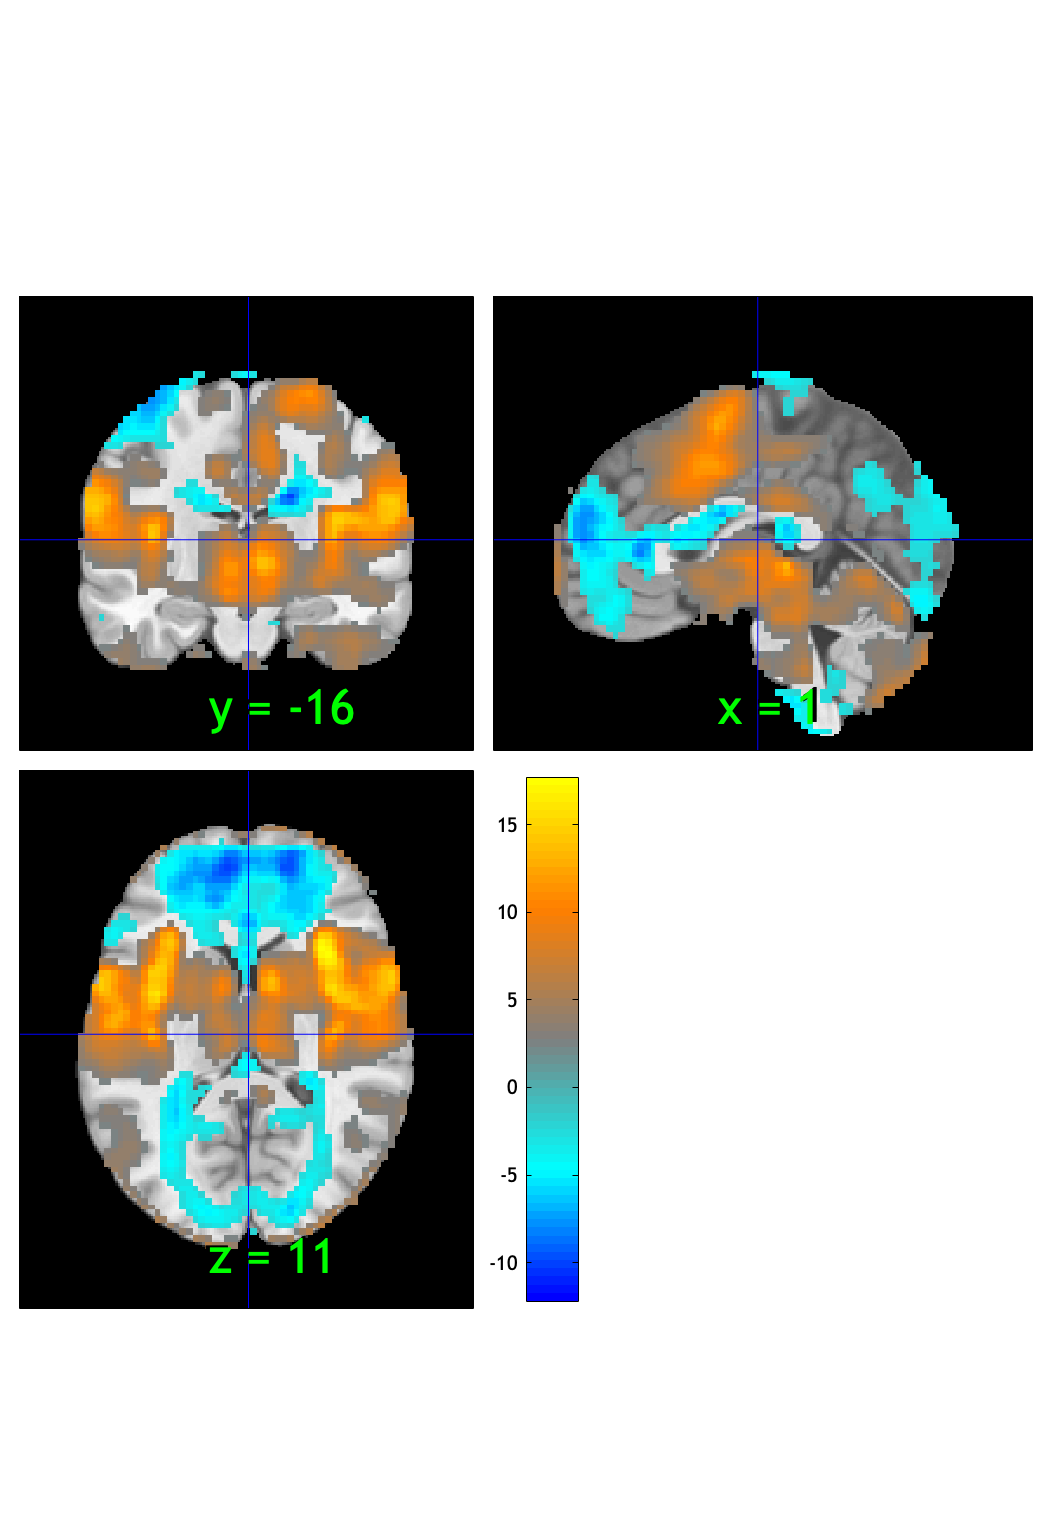

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:25:56 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0260
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 90
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_P_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000307

Image   1
 55 contig. clusters, sizes   1 to 28846
Positive effect: 22561 voxels, min p-value: 0.00000000
Negative effect: 8080 voxels, min p-value: 0.00000000


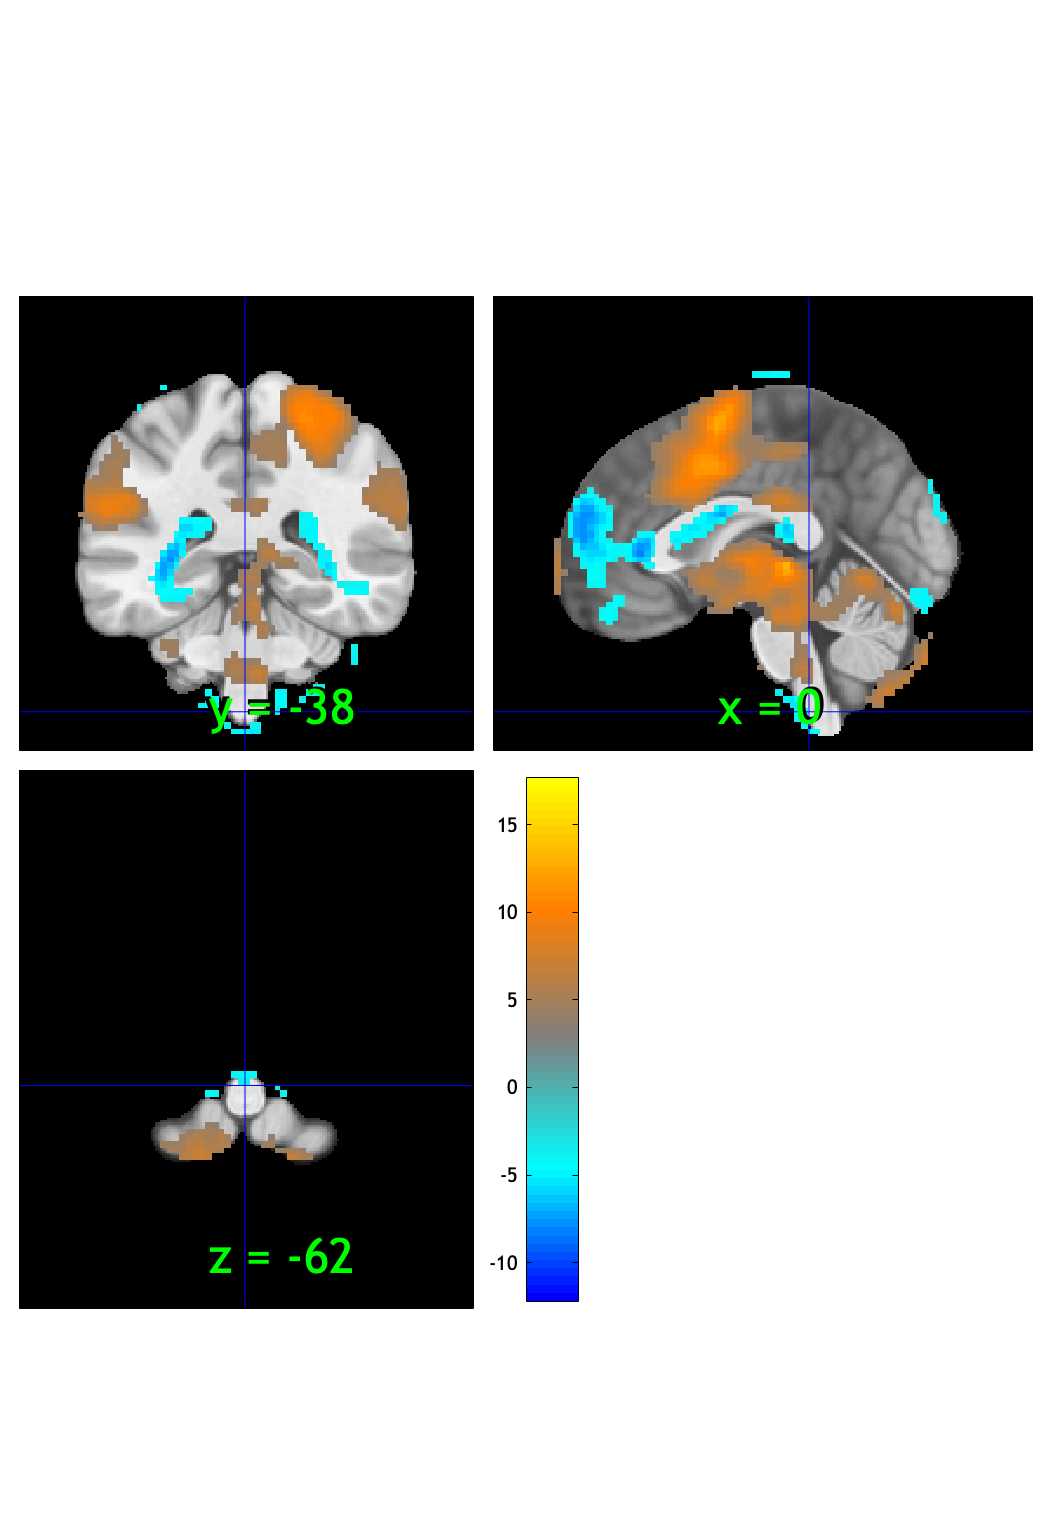

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:26:00 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 3.0684e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 90
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_P_fdr-001.nii



fdr_t0001 = threshold(t, .0001, 'fdr');

Image   1 FDR q < 0.000 threshold is 0.000024

Image   1
 47 contig. clusters, sizes   1 to 15216
Positive effect: 18642 voxels, min p-value: 0.00000000
Negative effect: 5611 voxels, min p-value: 0.00000000


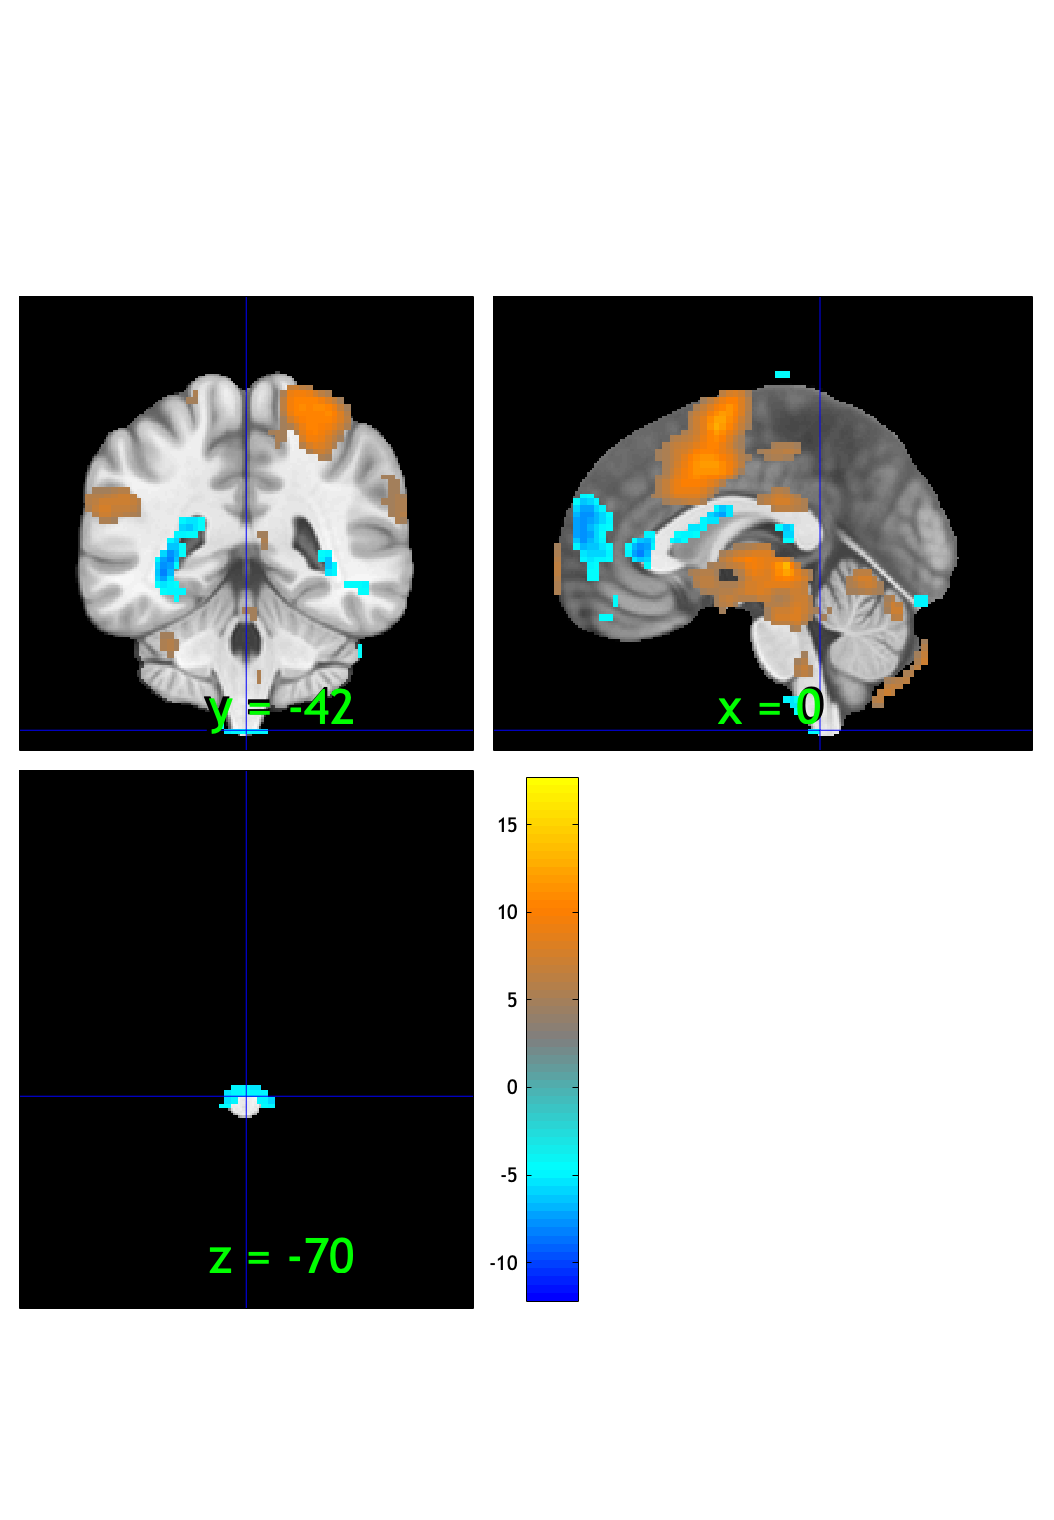

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:26:04 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


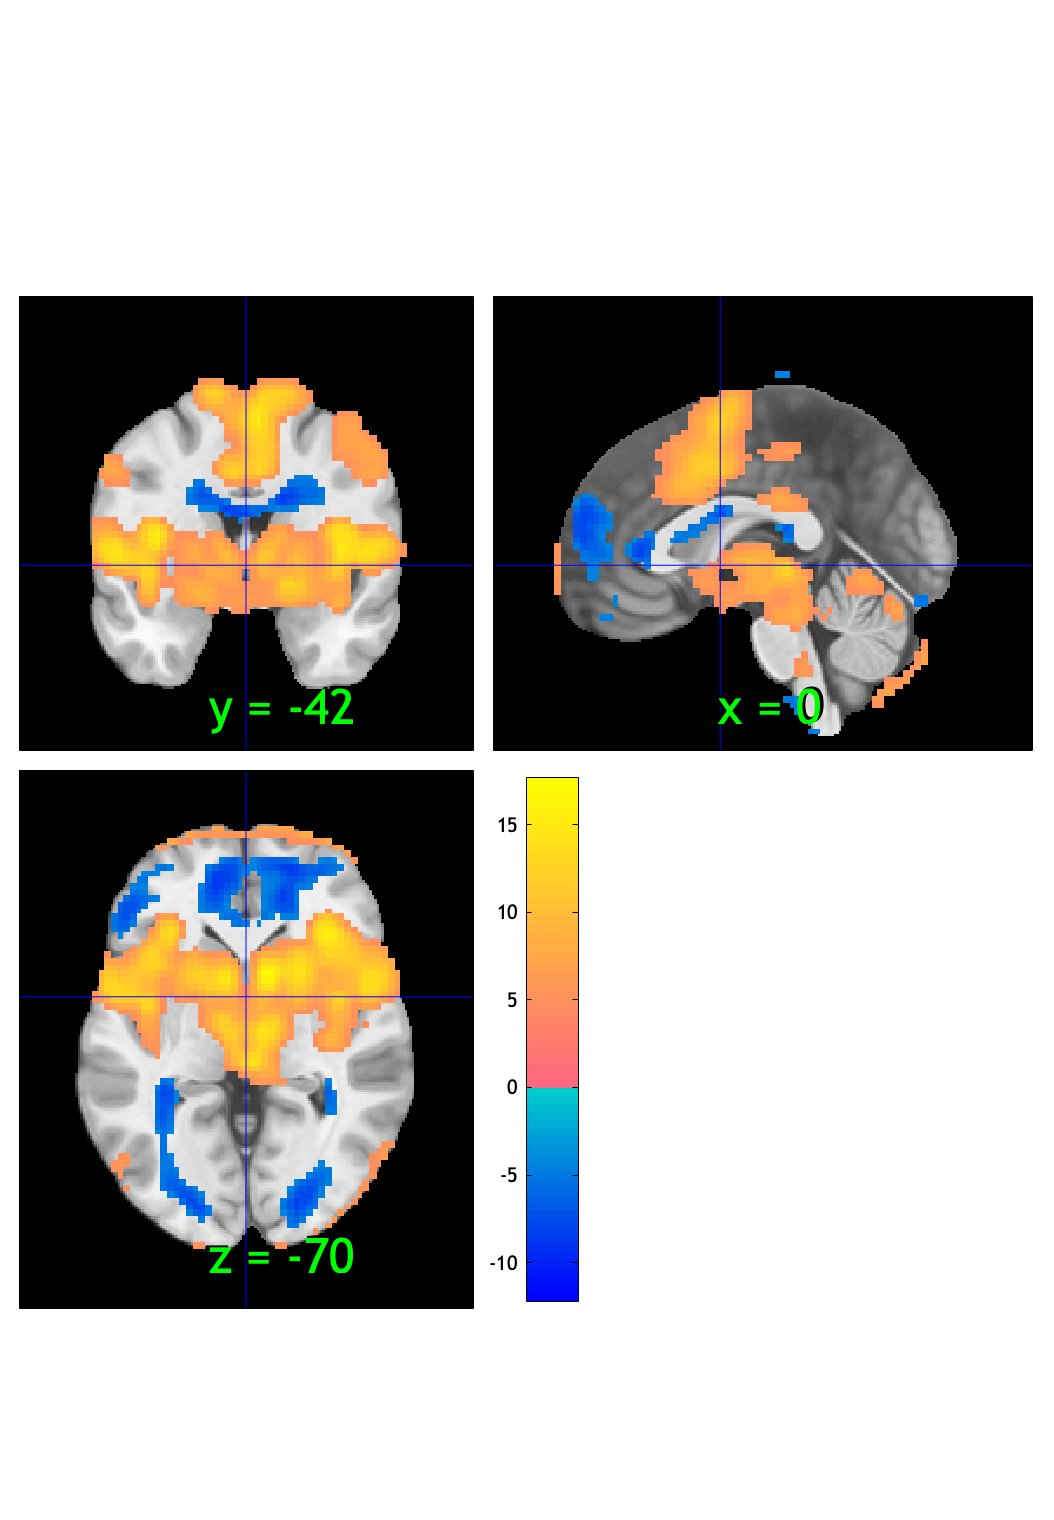

orthviews(fdr_t0001);

drawnow, snapnow;
fdr_t0001.dat = fdr_t0001.dat.*fdr_t0001.sig

fdr_t0001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 2.4199e-05
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 90
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t0001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-0001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_P_fdr-0001.nii



create_figure('montage'); axis off;
montage(fdr_t0001);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 600 voxels displayed, 23653 not displayed on these slices
sagittal montage: 750 voxels displayed, 23503 not displayed on these slices
sagittal montage: 597 voxels displayed, 23656 not displayed on these slices
axial montage: 4565 voxels displayed, 19688 not displayed on these slices
axial montage: 4775 voxels displayed, 19478 not displayed on these slices


drawnow, snapnow;

#### Pain > baseline :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high       words_high    
    _________    _______________    __________    _________________

     -0.2916     {'judgment'   }     0.38569      {'pain'         }
    -0.27215     {'judgments'  }     0.37341      {'somatosensory'}
    -0.26449     {'memory'     }     0.37266      {'painful'      }
    -0.25878     {'recognition'}     0.34084      {'sensory'      }
    -0.23689     {'mental'     }     0.33685      {'stimulation'  }
    -0.23589     {'episodic'   }     0.32928      {'noxious'      }
    -0.22884     {'person'     }      0.3288      {'heat'         }
    -0.21962     {'intention'  }     0.32222      {'motor'        }
    -0.20996     {'object'     }     0.30889      {'sensation'    }
    -0.20842

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain > baseline :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.1116	16.4243	0.0000	1.0000	***
Cog Wholebrain	-0.0591	-15.9004	0.0000	1.0000	***
Emo Wholebrain	-0.0527	-9.7542	0.0000	1.0000	***
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.11158     0.0067436     16.546    2.2204e-15     1.6976 
    {'Cog Wholebrain' }    -0.059091     0.0037042    -15.952    2.2204e-15    -1.6367 
    {'Emo Wholebrain' }    -0.052684     0.0053937    -9.7677    2.2204e-15    -1.0021 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [19.0004 20.0004 21.0004]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.10305     0.0063234     16.296    2.2204e-15       1.672
    {'Cog Wholebrain' }     -0.05342     0.0034836    -15.335    2.2204e-15     -1.5733
    {'Emo Wholebrain' }    -0.049513     0.0051363    -9.6397    2.2204e-15    -0.98901



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [22.0004 23.0004 24.0004]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

## Vicarious > baseline

clear all

#### Vicarious > baseline :: load dataset

contrast_of_interest = 'simple_stim_V';

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel';
nifti_save_fname_prefix = 'model02-CESO_epoch-stim';

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';
contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

#### Vicarious > baseline :: `check data coverage`

Grouping contiguous voxels:   1 regions


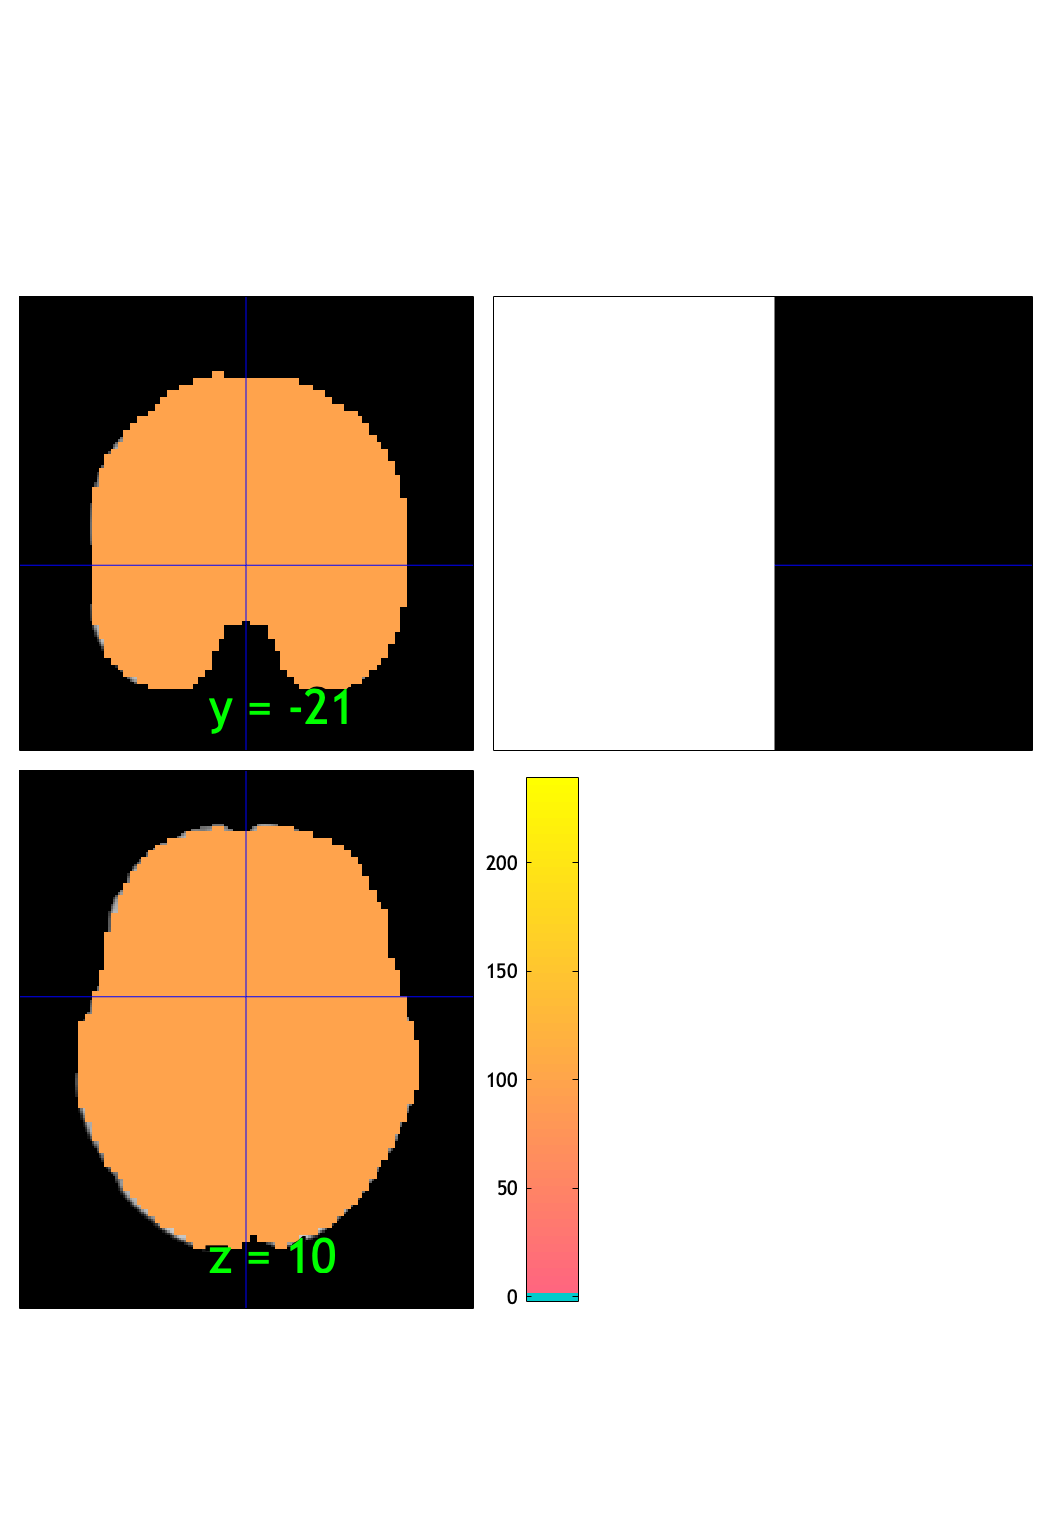

ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious > baseline :: Plot diagnostics, before l2norm

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 44.21%
Expected 4.75 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 9 images		Cases 28 35 50 52 73 75 84 87 95 

Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.53%
Expected 4.75 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 28 52 61 66 

Mahalanobis (cov and corr, q<0.05 corrected):
  0 images 
                               Outlier_count    Percentage
                         

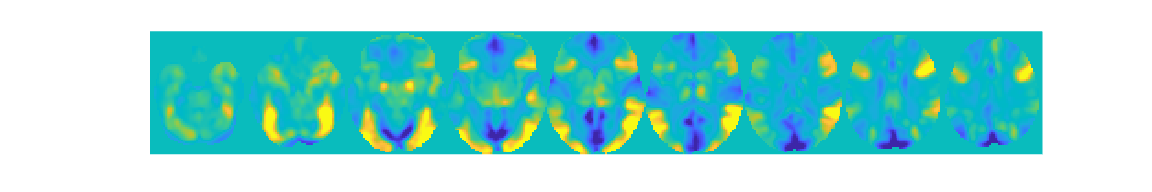

wh_outlier_uncorr = 95×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 95×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Vicarious > baseline :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious > baseline :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 95


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×21 char]
              fullpath: [95×112 char]
           files_exist: [95×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×21 char]
              fullpath: [95×112 char]
           files_exist: [95×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×21 char]
              fullpath: [95×112 char]
           files_exist: [95×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 0 participants, size is now 95


#### Vicarious > baseline :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious > baseline :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


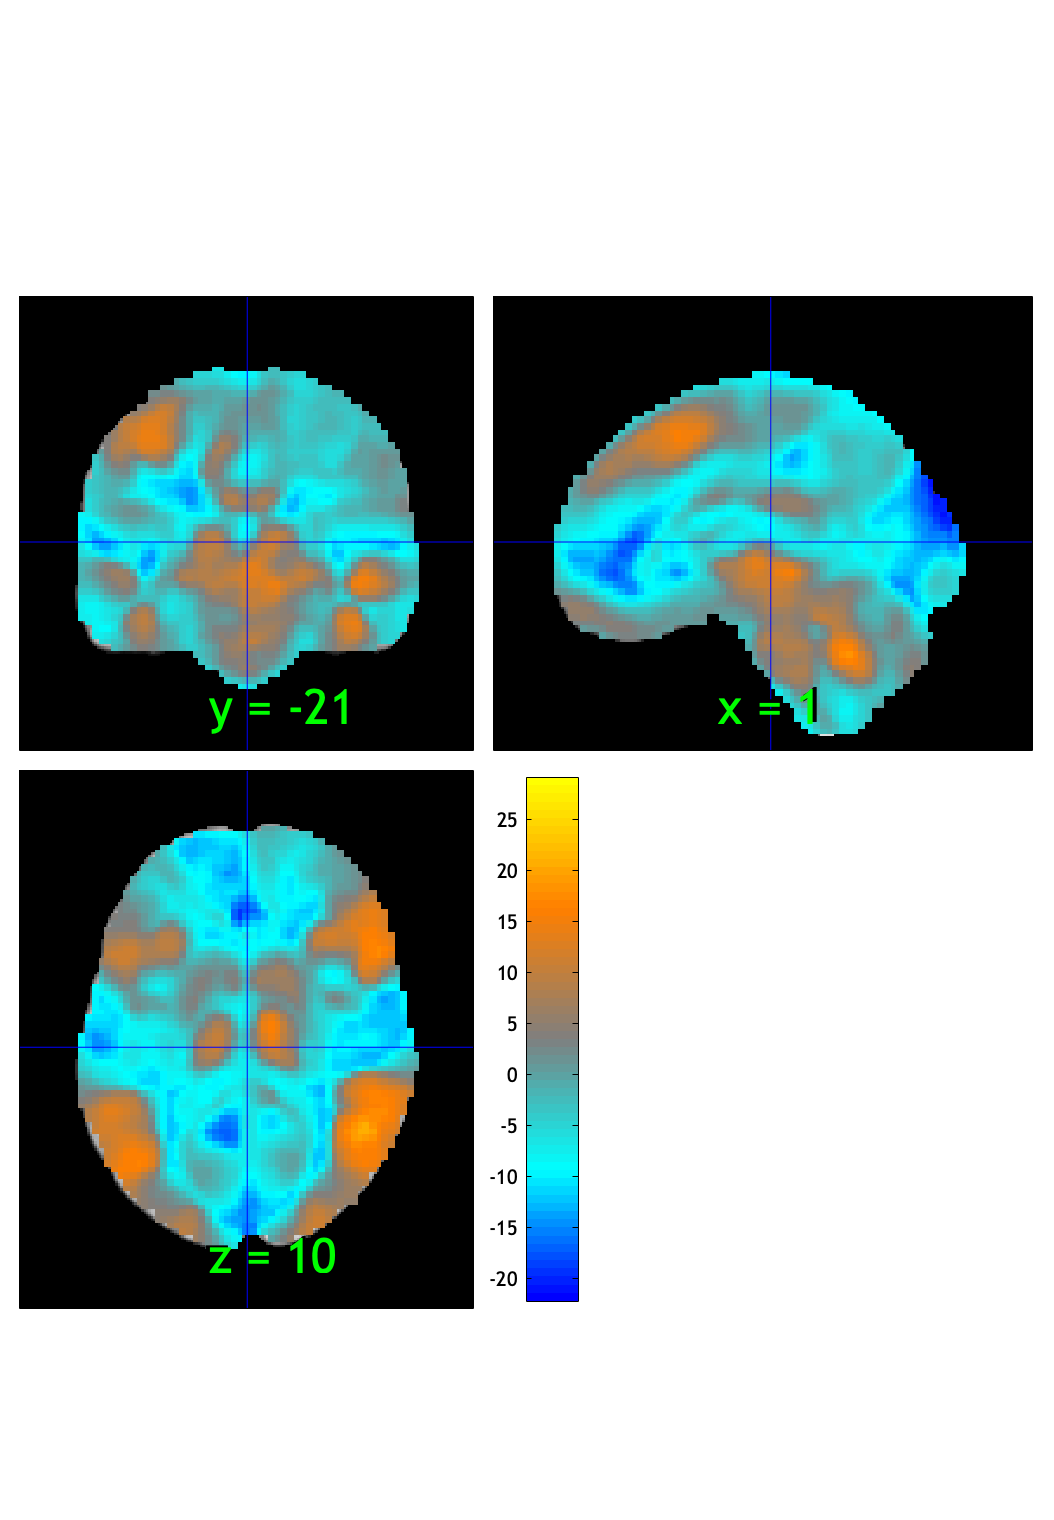

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:31:21 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.038810

Image   1
 14 contig. clusters, sizes   1 to 77433
Positive effect: 34352 voxels, min p-value: 0.00000000
Negative effect: 43156 voxels, min p-value: 0.00000000


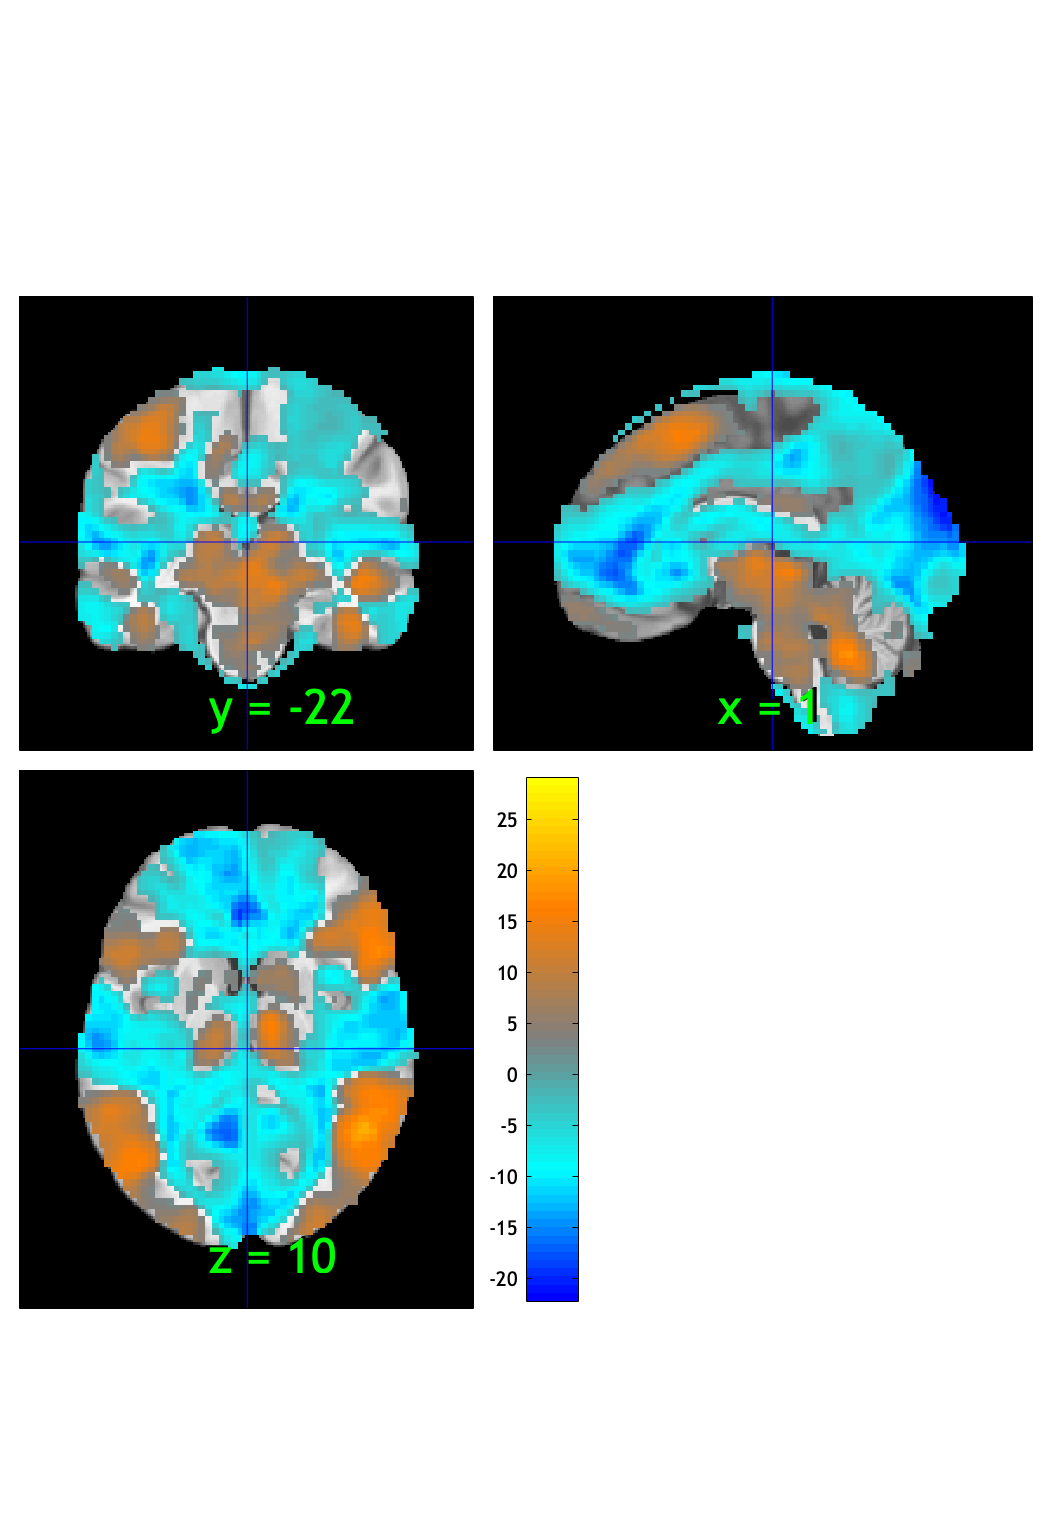

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:31:26 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0388
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 94
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_V_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000636

Image   1
 11 contig. clusters, sizes   1 to 63358
Positive effect: 28279 voxels, min p-value: 0.00000000
Negative effect: 35231 voxels, min p-value: 0.00000000


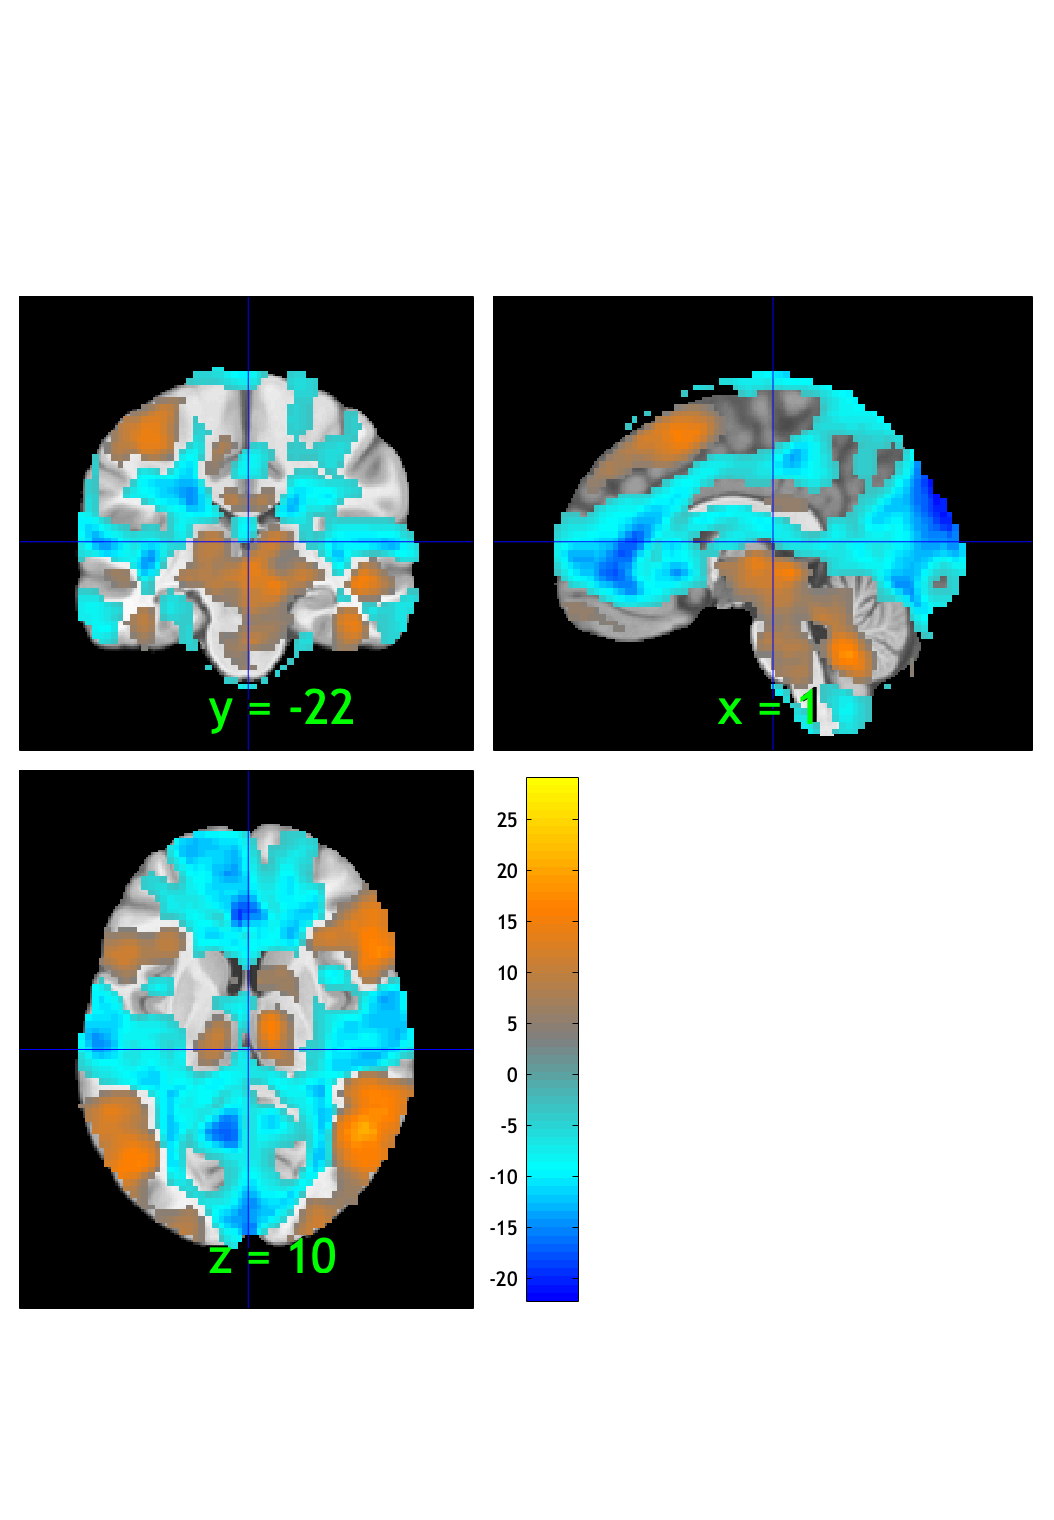

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:31:32 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 6.3598e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 94
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_V_fdr-001.nii




fdr_t0001 = threshold(t, .0001, 'fdr');

Image   1 FDR q < 0.000 threshold is 0.000057

Image   1
  7 contig. clusters, sizes   1 to 57081
Positive effect: 25698 voxels, min p-value: 0.00000000
Negative effect: 31477 voxels, min p-value: 0.00000000


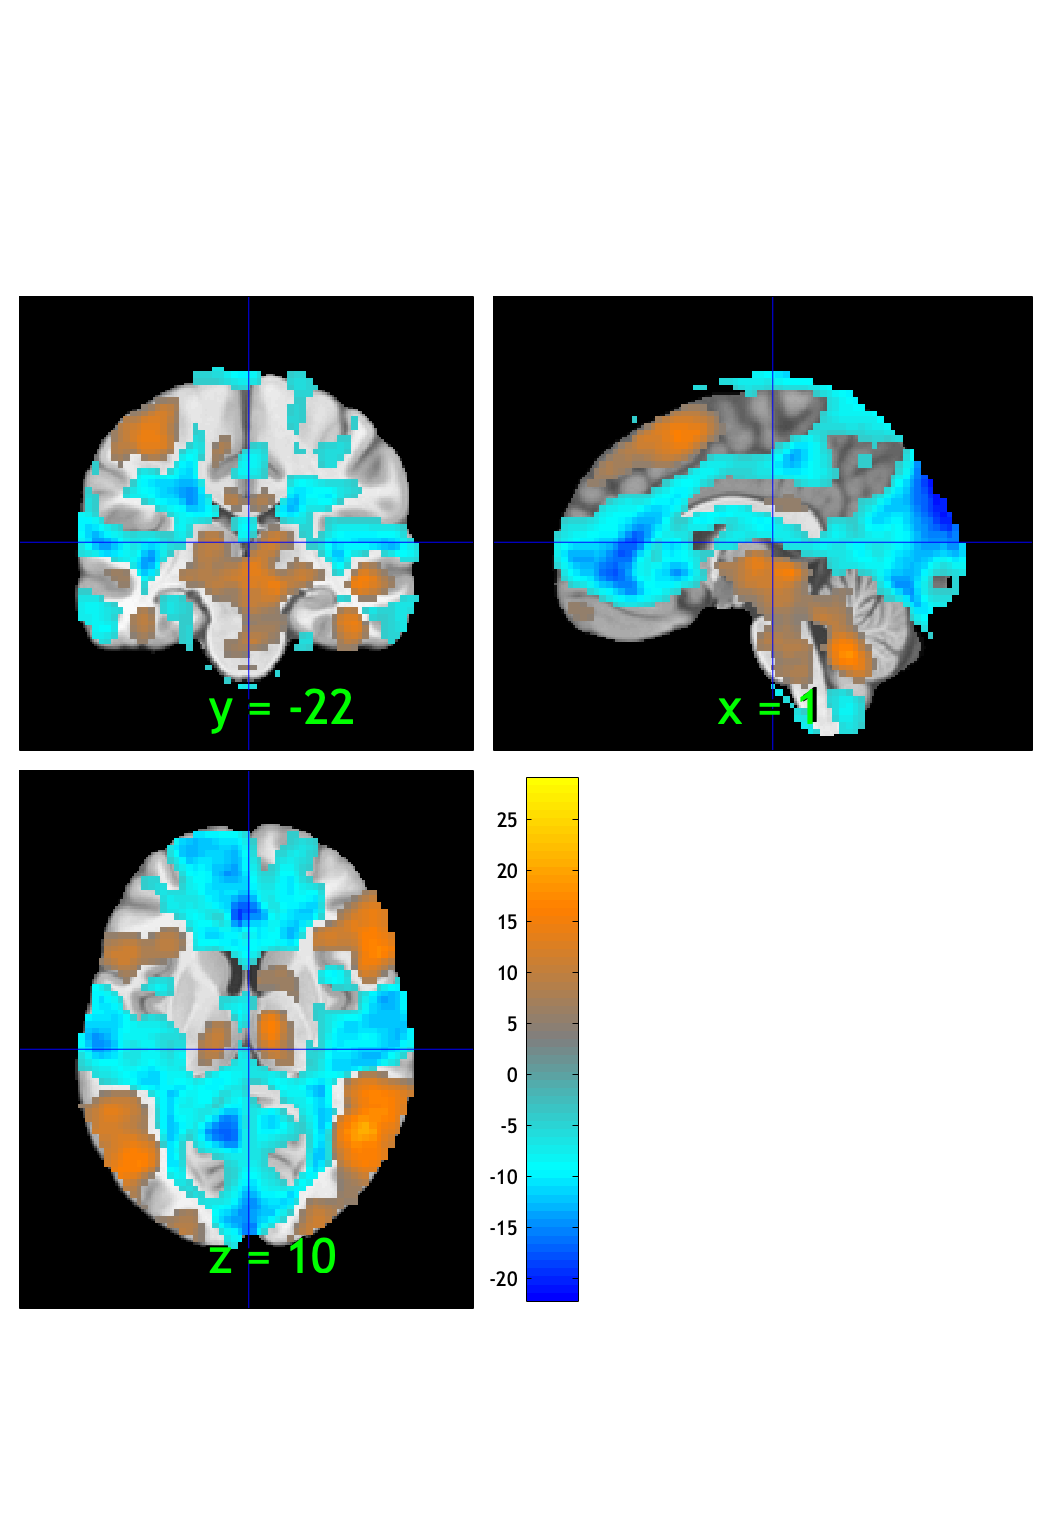

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:31:38 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


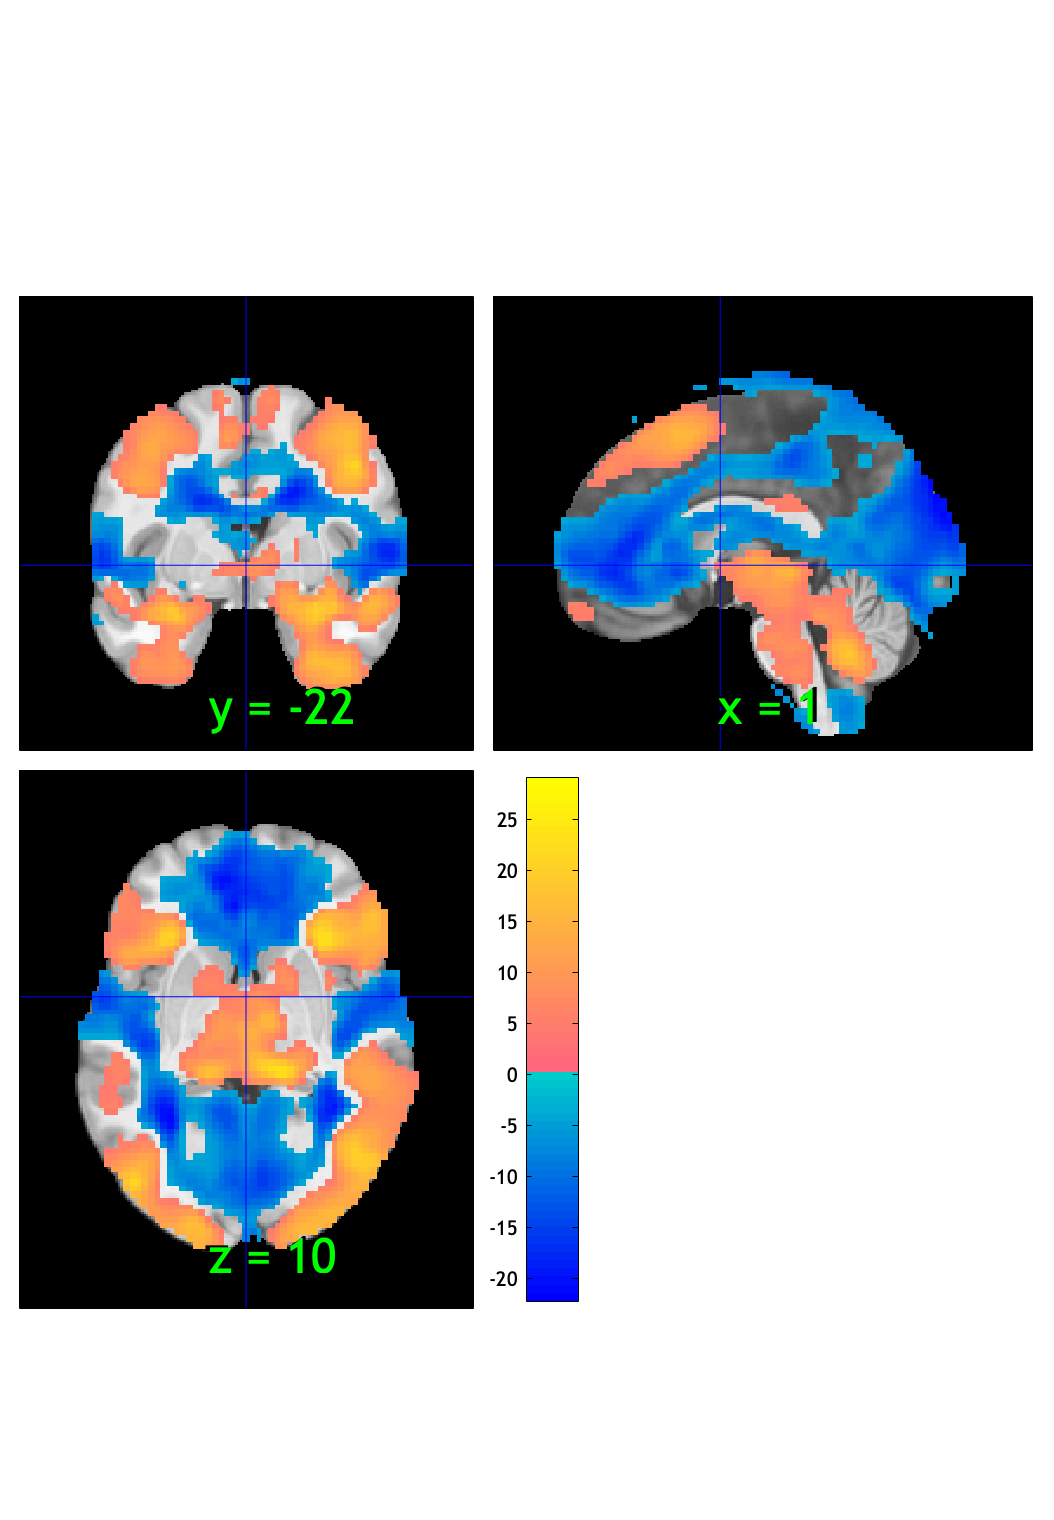

orthviews(fdr_t0001);

drawnow, snapnow;
fdr_t0001.dat = fdr_t0001.dat.*fdr_t0001.sig

fdr_t0001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 5.7220e-05
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 94
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t0001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-0001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_V_fdr-0001.nii




create_figure('montage'); axis off;
montage(fdr_t0001);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1594 voxels displayed, 55581 not displayed on these slices
sagittal montage: 1398 voxels displayed, 55777 not displayed on these slices
sagittal montage: 1489 voxels displayed, 55686 not displayed on these slices
axial montage: 11104 voxels displayed, 46071 not displayed on these slices
axial montage: 12027 voxels displayed, 45148 not displayed on these slices


drawnow, snapnow;

#### Vicarious > baseline :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low        testr_high      words_high  
    _________    ________________    __________    ______________

    -0.26172     {'age'         }      0.2721      {'visual'    }
    -0.24794     {'time'        }     0.26847      {'object'    }
    -0.22074     {'default'     }     0.26088      {'perception'}
    -0.22006     {'restingstate'}     0.25999      {'identity'  }
    -0.21763     {'disorder'    }     0.25317      {'objects'   }
    -0.20624     {'depression'  }      0.2488      {'face'      }
    -0.20576     {'trait'       }     0.24475      {'gesture'   }
    -0.20508     {'personal'    }     0.23914      {'faces'     }
    -0.20385     {'outcomes'    }     0.23075      {'actions'   }
    -0.20288     {'positive'    } 

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Vicarious > baseline :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.1423	-31.3392	0.0000	1.0000	***
Cog Wholebrain	-0.0269	-10.3607	0.0000	1.0000	***
Emo Wholebrain	0.1587	35.1819	0.0000	1.0000	***
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.14225     0.0044757    -31.784    2.2204e-15    -3.2609 
    {'Cog Wholebrain' }    -0.026885     0.0025941    -10.364    2.2204e-15    -1.0633 
    {'Emo Wholebrain' }      0.15872     0.0044366     35.775    2.2204e-15     3.6705 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [18.0005 19.0005 20.0005]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.14181     0.0044464    -31.894    2.2204e-15    -3.2722 
    {'Cog Wholebrain' }    -0.025597     0.0024817    -10.314    2.2204e-15    -1.0582 
    {'Emo Wholebrain' }      0.15945     0.0044436     35.883    2.2204e-15     3.6816 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [21.0005 22.0005 23.0005]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

## Cognitive > baseline

#### Cognitive > baseline :: load dataset

contrast_of_interest = 'simple_stim_C';

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel';
nifti_save_fname_prefix = 'model02-CESO_epoch-stim';

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';
contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

#### Cognitive > baseline :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Cognitive > baseline :: Plot diagnostics, before l2norm

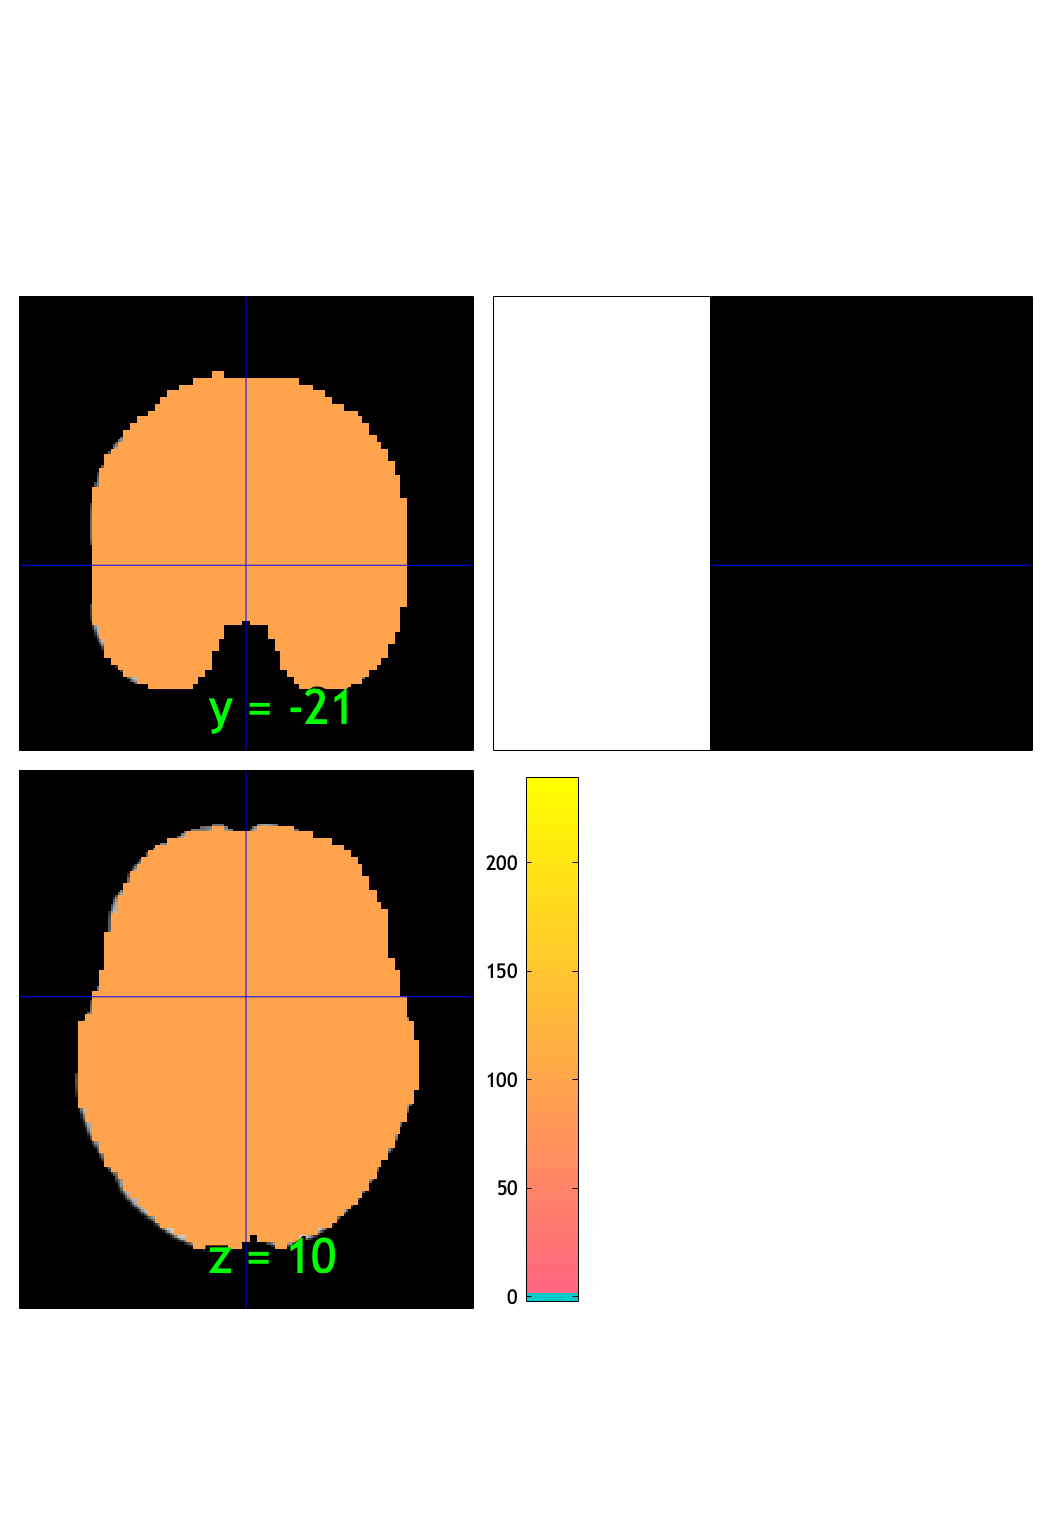

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 35.79%
Expected 4.75 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 59 84 
Uncorrected: 5 images		Cases 35 52 59 84 95 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 42.11%
Expected 4.75 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 5 images		Cases 3 49 52 78 84 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                              

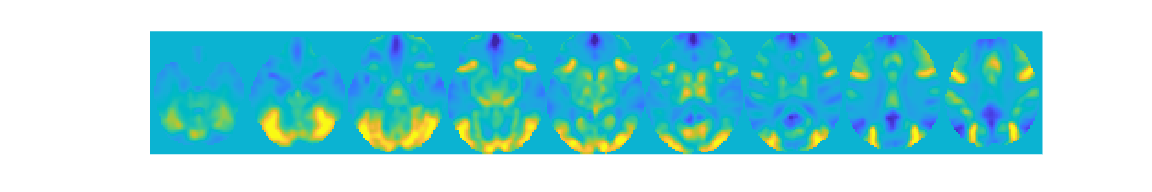

wh_outlier_uncorr = 95×1 logical array
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 95×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive > baseline :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive > baseline :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 95


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×91 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [91×21 char]
              fullpath: [95×112 char]
           files_exist: [95×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×91 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [91×21 char]
              fullpath: [91×112 char]
           files_exist: [95×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×91 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [91×21 char]
              fullpath: [91×112 char]
           files_exist: [91×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 4 participants, size is now 91


#### Cognitive > baseline:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive > PV :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


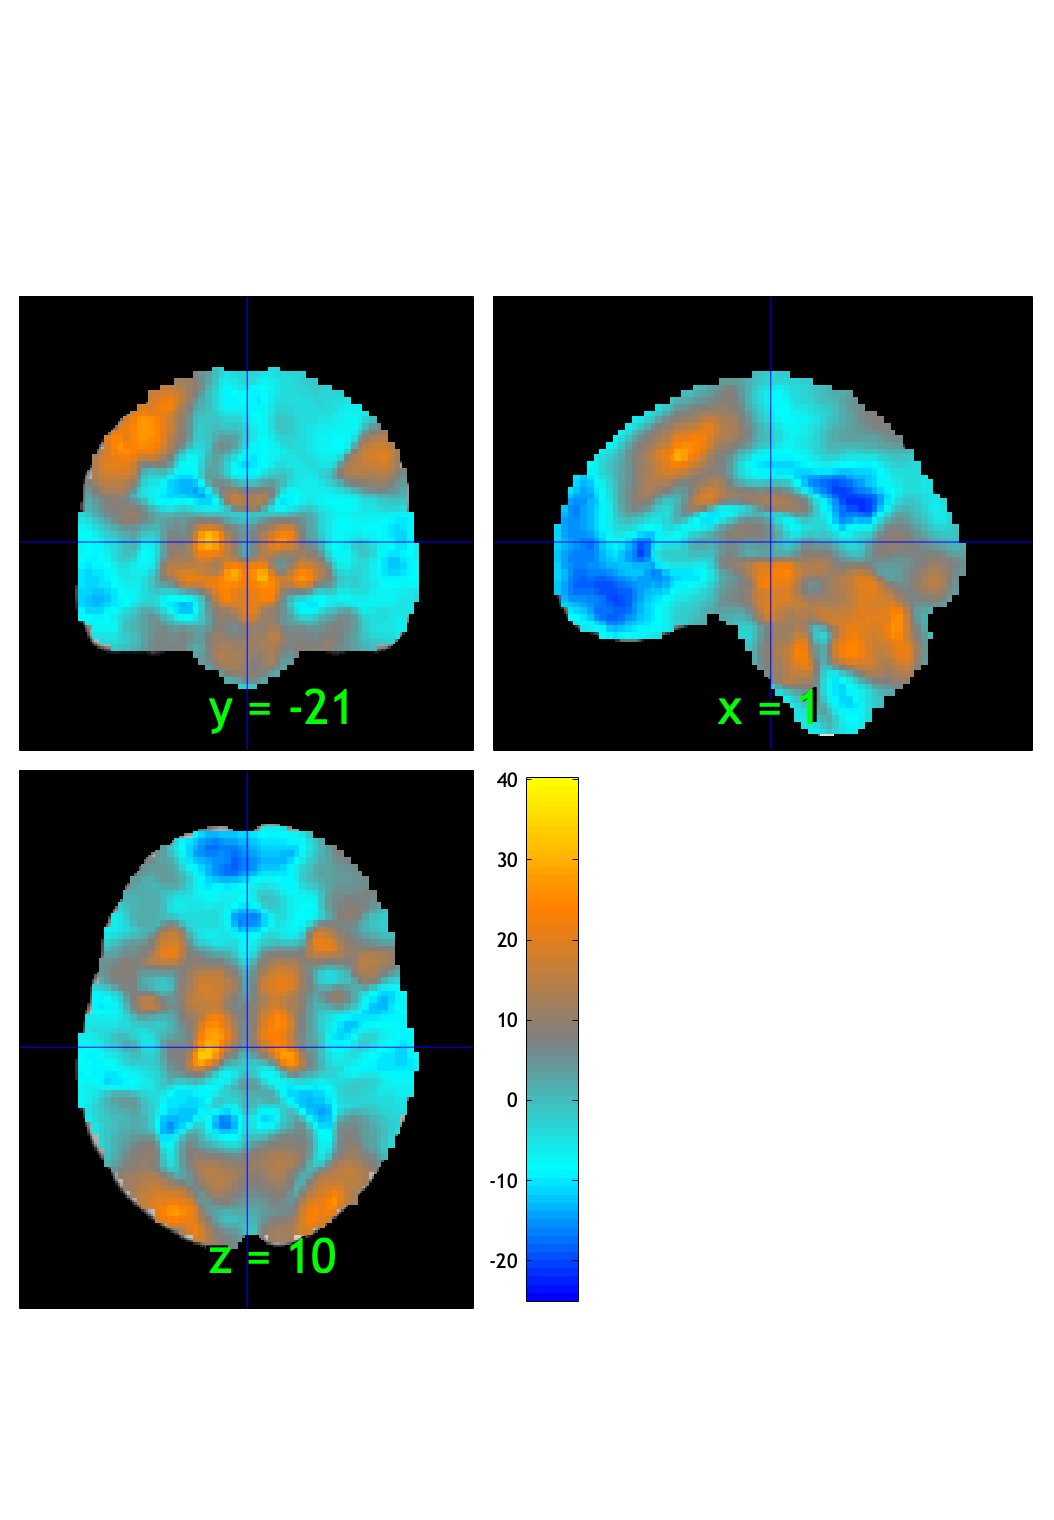

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:37:03 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.042822

Image   1
  3 contig. clusters, sizes   1 to 85498
Positive effect: 49649 voxels, min p-value: 0.00000000
Negative effect: 35856 voxels, min p-value: 0.00000000


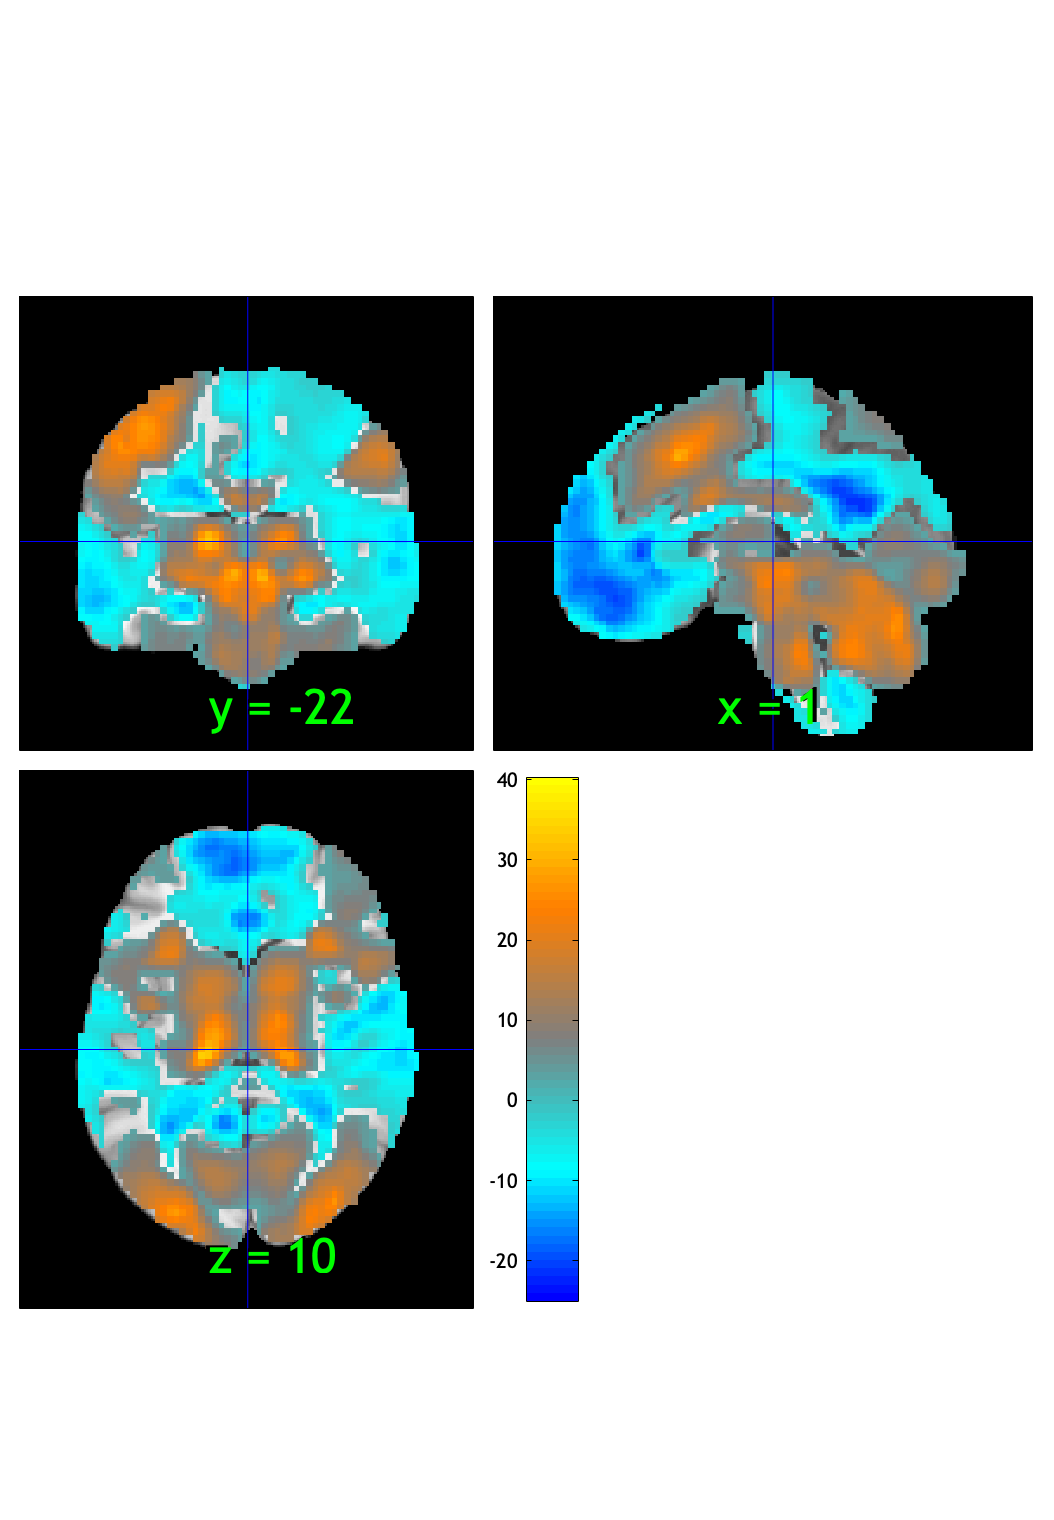

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:37:07 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0428
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 90
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_C_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000755

Image   1
  9 contig. clusters, sizes   1 to 75225
Positive effect: 44737 voxels, min p-value: 0.00000000
Negative effect: 30633 voxels, min p-value: 0.00000000


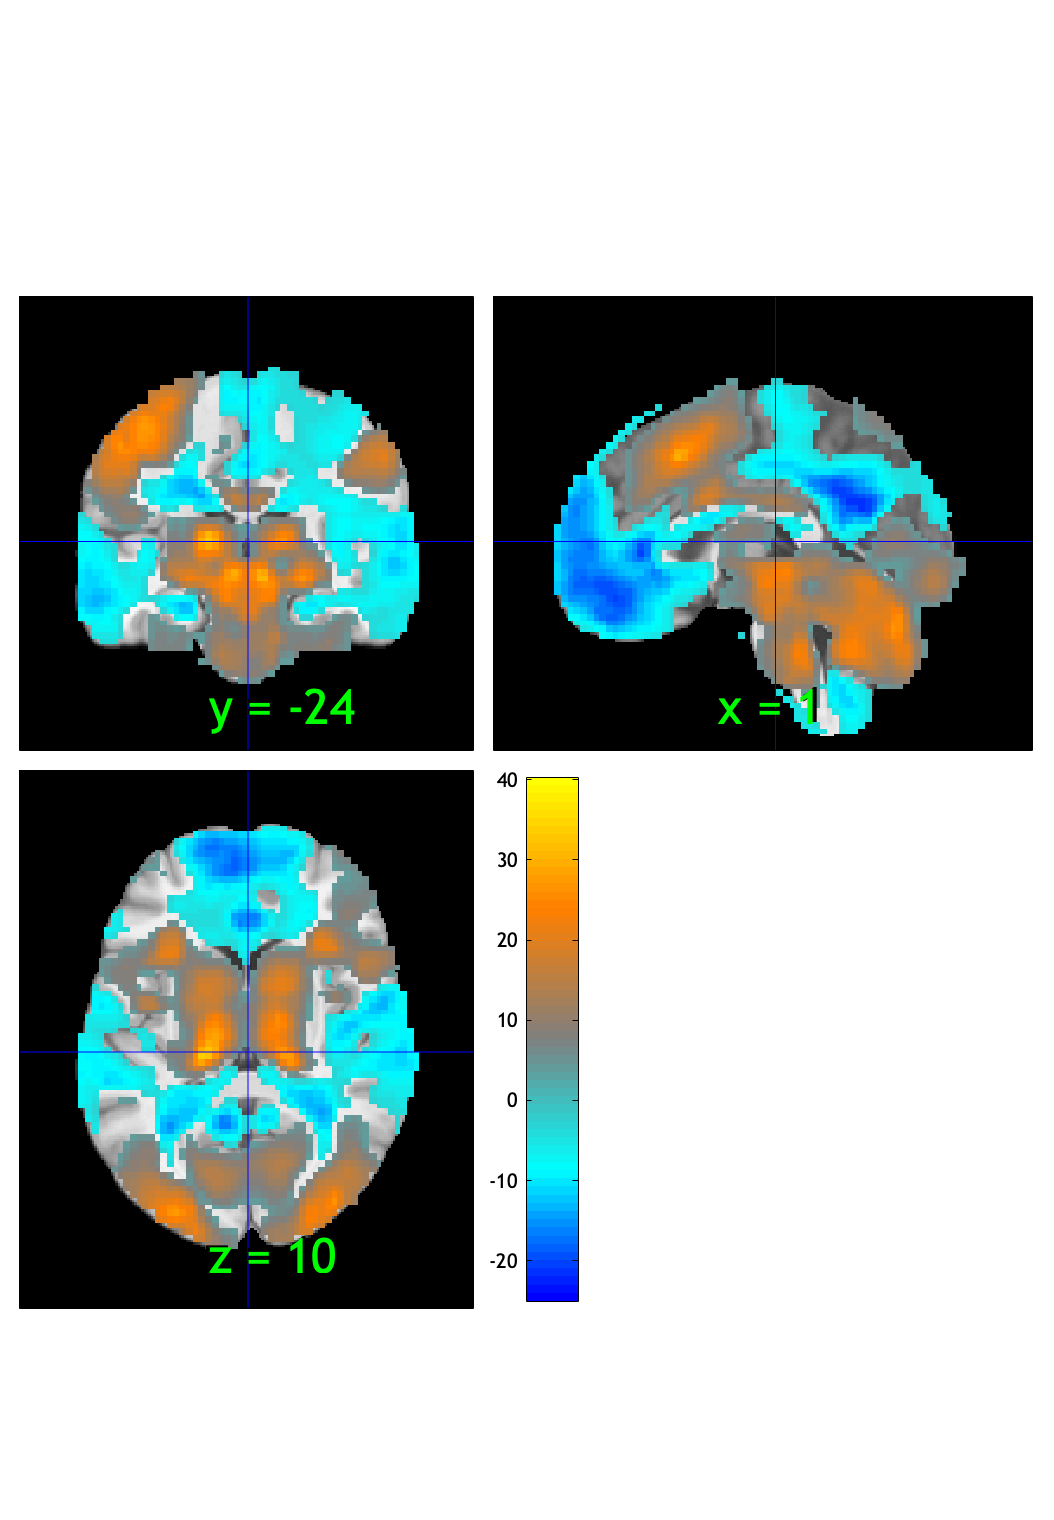

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:37:10 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 7.5483e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 90
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_C_fdr-001.nii



fdr_t0001 = threshold(t, .0001, 'fdr');

Image   1 FDR q < 0.000 threshold is 0.000071

Image   1
  8 contig. clusters, sizes   2 to 70332
Positive effect: 42455 voxels, min p-value: 0.00000000
Negative effect: 28073 voxels, min p-value: 0.00000000


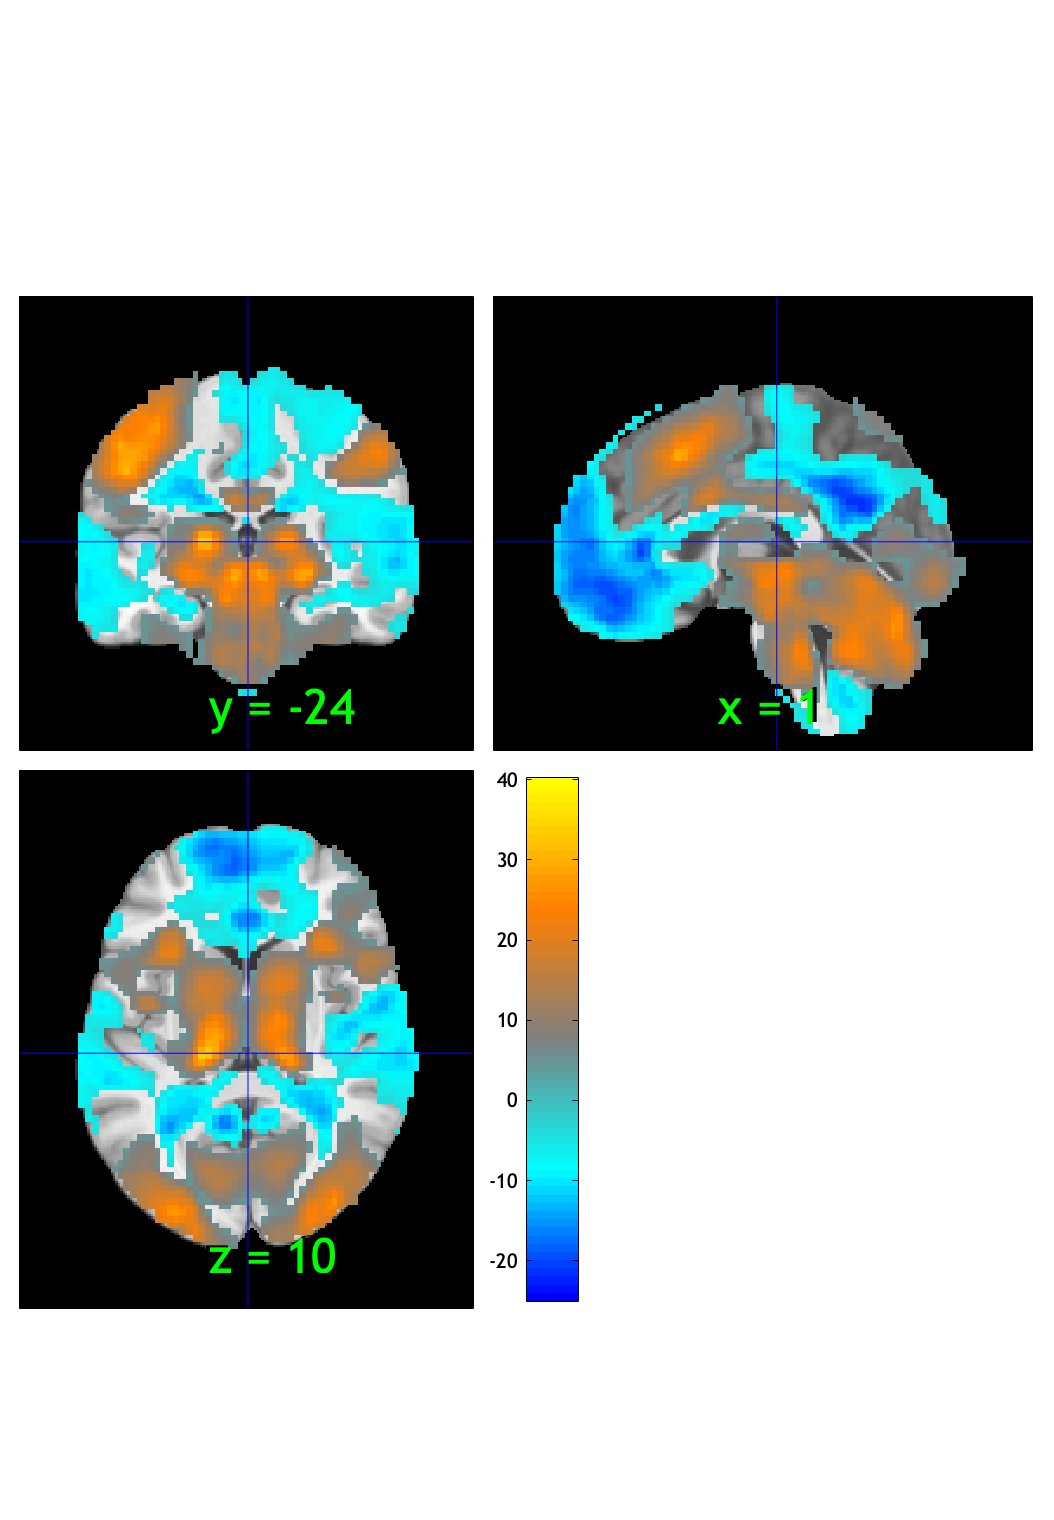

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:37:14 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


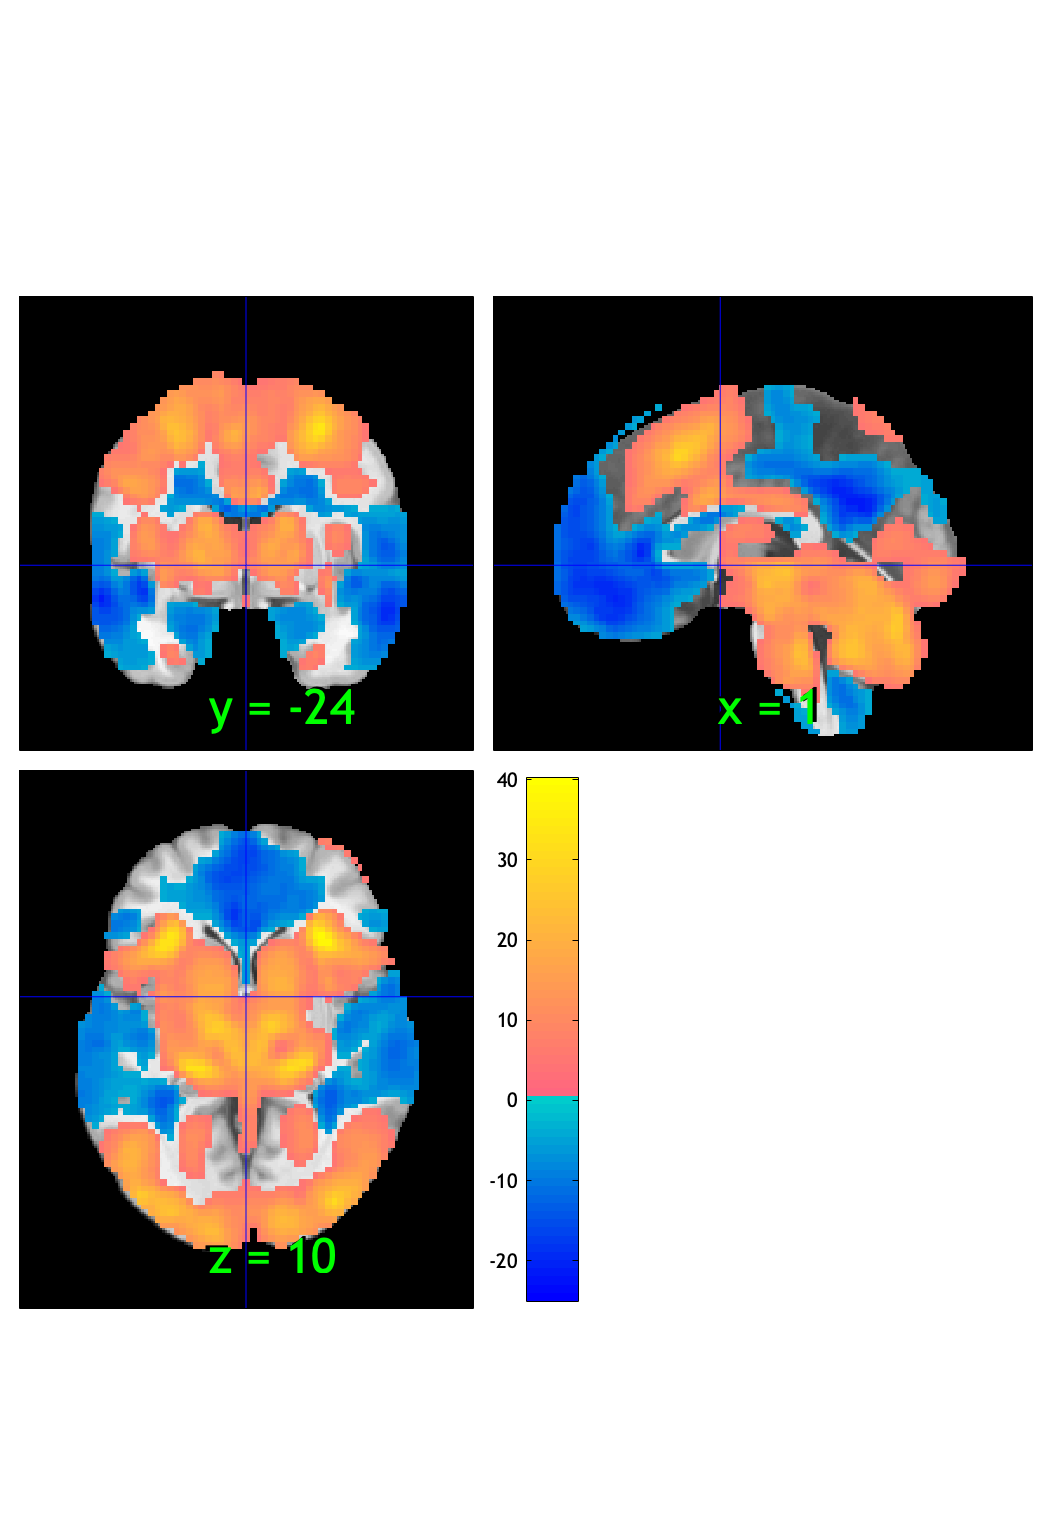

orthviews(fdr_t0001);

drawnow, snapnow;
fdr_t0001.dat = fdr_t0001.dat.*fdr_t0001.sig

fdr_t0001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 7.0572e-05
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 90
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t0001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-0001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimsimple_stim_C_fdr-0001.nii




create_figure('montage'); axis off;
montage(fdr_t0001);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1836 voxels displayed, 68692 not displayed on these slices
sagittal montage: 1826 voxels displayed, 68702 not displayed on these slices
sagittal montage: 1810 voxels displayed, 68718 not displayed on these slices
axial montage: 13372 voxels displayed, 57156 not displayed on these slices
axial montage: 14521 voxels displayed, 56007 not displayed on these slices


drawnow, snapnow;

#### Cognitive > baseline :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low     words_low      testr_high      words_high   
    _________    ____________    __________    _______________

    -0.38983     {'trait'   }     0.47603      {'visual'     }
    -0.35521     {'personal'}     0.34115      {'object'     }
    -0.35343     {'person'  }     0.31573      {'letter'     }
    -0.34353     {'positive'}     0.31218      {'attention'  }
    -0.33747     {'rating'  }     0.30898      {'shape'      }
    -0.33565     {'negative'}     0.30688      {'objects'    }
    -0.33199     {'age'     }     0.30421      {'maintenance'}
    -0.31604     {'self'    }      0.2958      {'numbers'    }
     -0.3043     {'social'  }     0.28808      {'eye'        }
    -0.29631     {'affect'  }      0.2858      {'execution'  }



% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Cognitive > baseline :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0559	-15.9014	0.0000	1.0000	***
Cog Wholebrain	-0.0281	-10.8146	0.0000	1.0000	***
Emo Wholebrain	0.0781	22.7600	0.0000	1.0000	***
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.055907      0.003508    -15.937    2.2204e-15    -1.6351 
    {'Cog Wholebrain' }    -0.028076     0.0025947    -10.821    2.2204e-15    -1.1102 
    {'Emo Wholebrain' }     0.078061     0.0034172     22.844    2.2204e-15     2.3437 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [17.0006 18.0006 19.0006]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.052666     0.0033784    -15.589    2.2204e-15    -1.5994 
    {'Cog Wholebrain' }    -0.025437     0.0024629    -10.328    2.2204e-15    -1.0597 
    {'Emo Wholebrain' }     0.073894     0.0033542      22.03    2.2204e-15     2.2603 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [20.0006 21.0006 22.0006]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

## Motor > baseline

#### Motor > baseline :: load dataset

contrast_of_interest = 'motor';

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel';
nifti_save_fname_prefix = 'model02-CESO_epoch-stim';

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';
contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

#### Motor > baseline :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Motor > baseline :: Plot diagnostics, before l2norm

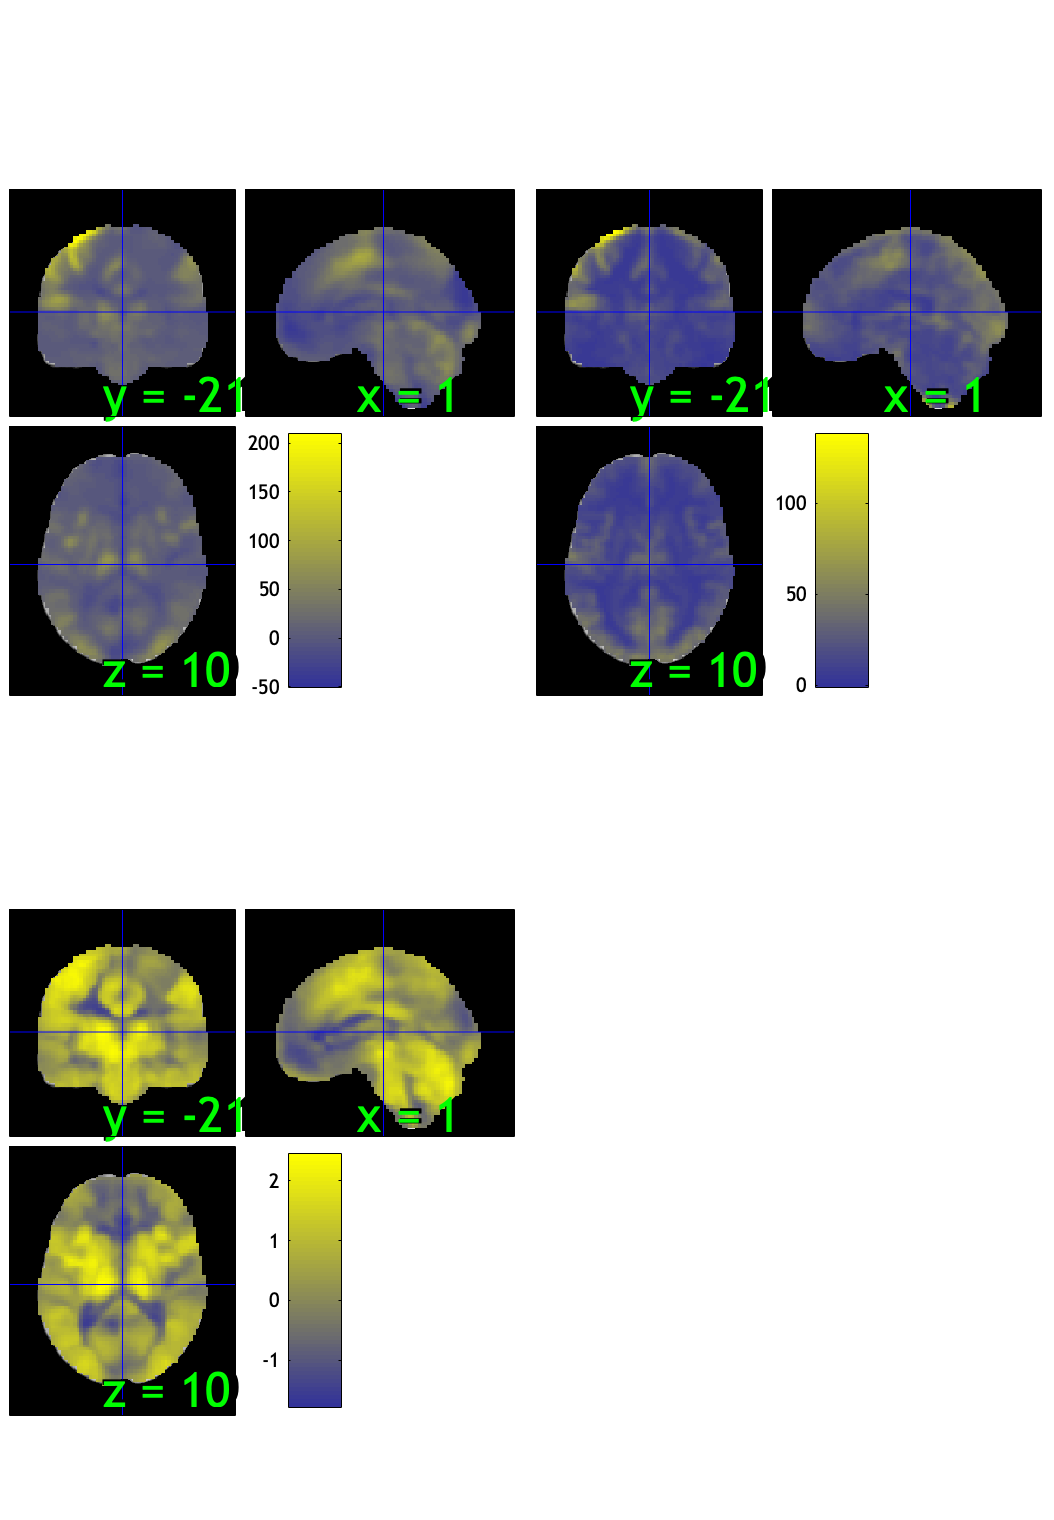

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 43.30%
Expected 4.85 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 31 52 
Uncorrected: 6 images		Cases 4 18 28 31 37 52 

Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.36%
Expected 4.85 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 7 images		Cases 3 25 48 54 69 81 86 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                      

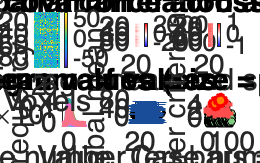

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:42:13 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

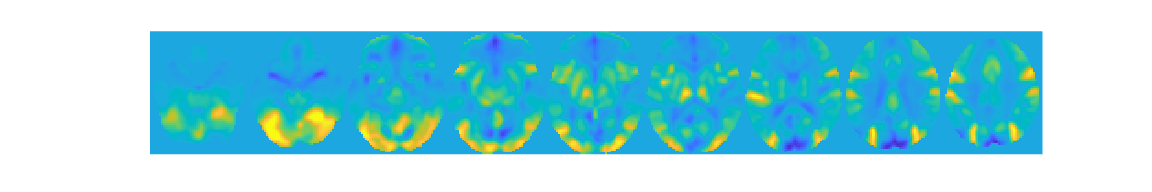

wh_outlier_uncorr = 97×1 logical array
   0
   0
   1
   1
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 97×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Motor > baseline :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Motor > baseline :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 97


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×21 char]
              fullpath: [97×112 char]
           files_exist: [97×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×21 char]
              fullpath: [95×112 char]
           files_exist: [97×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×21 char]
              fullpath: [95×112 char]
           files_exist: [95×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 2 participants, size is now 95


#### Motor > baseline:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Motor > baseline :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


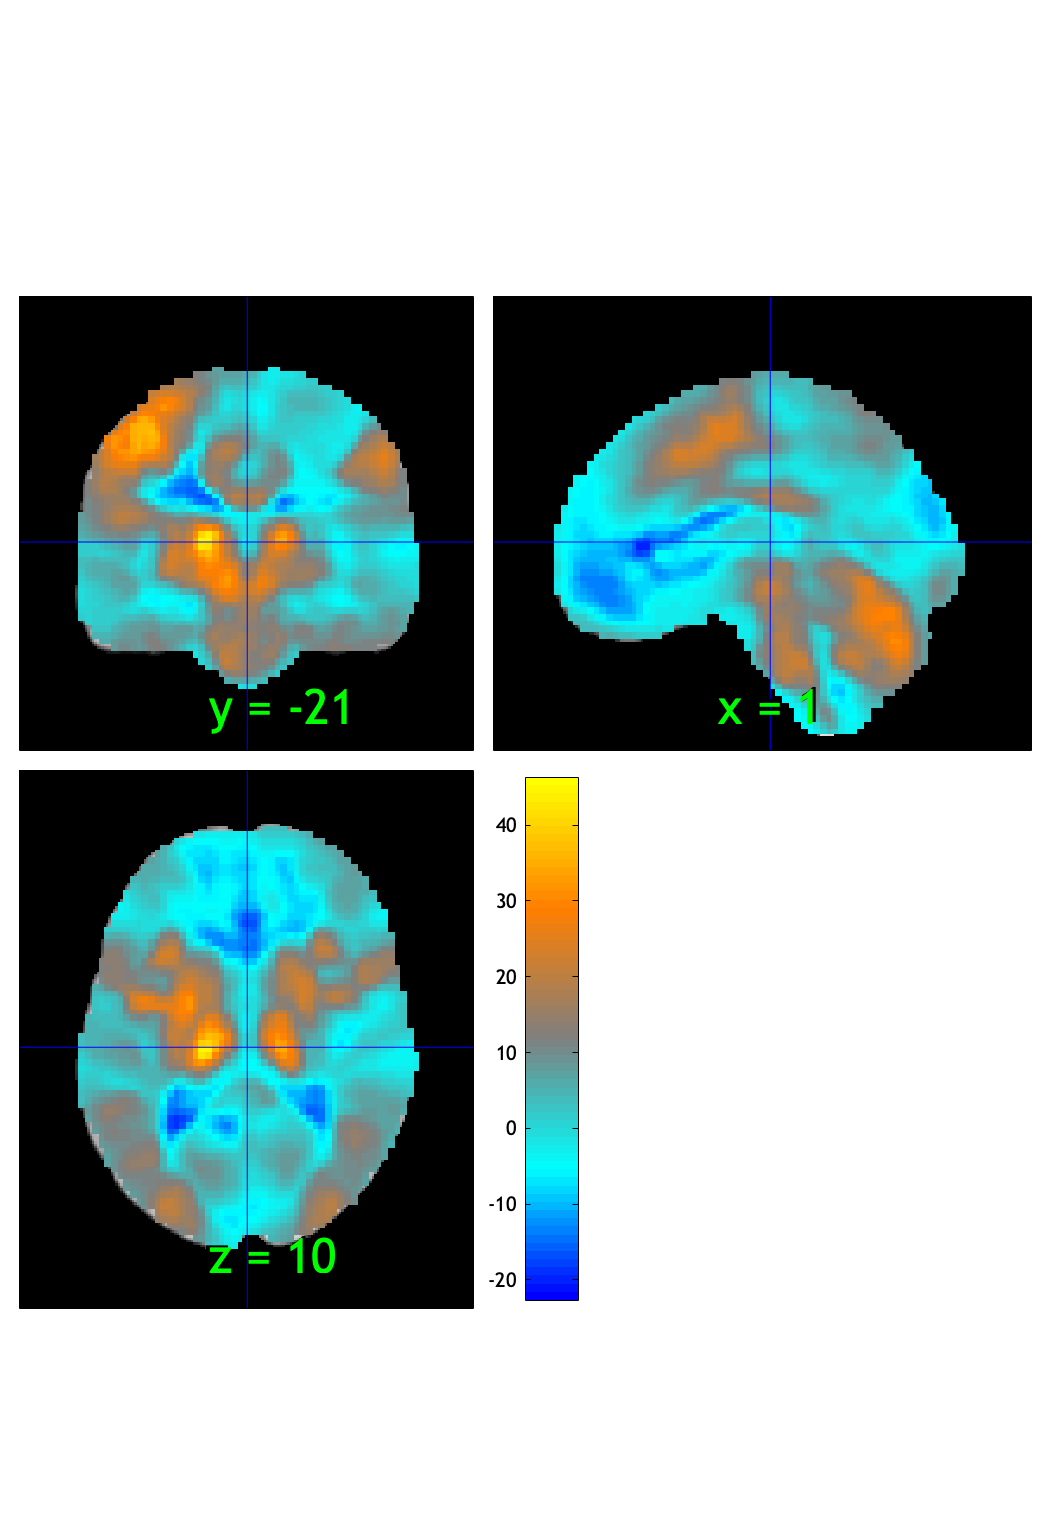

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:42:32 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.041946

Image   1
  5 contig. clusters, sizes   1 to 83719
Positive effect: 66125 voxels, min p-value: 0.00000000
Negative effect: 17634 voxels, min p-value: 0.00000000


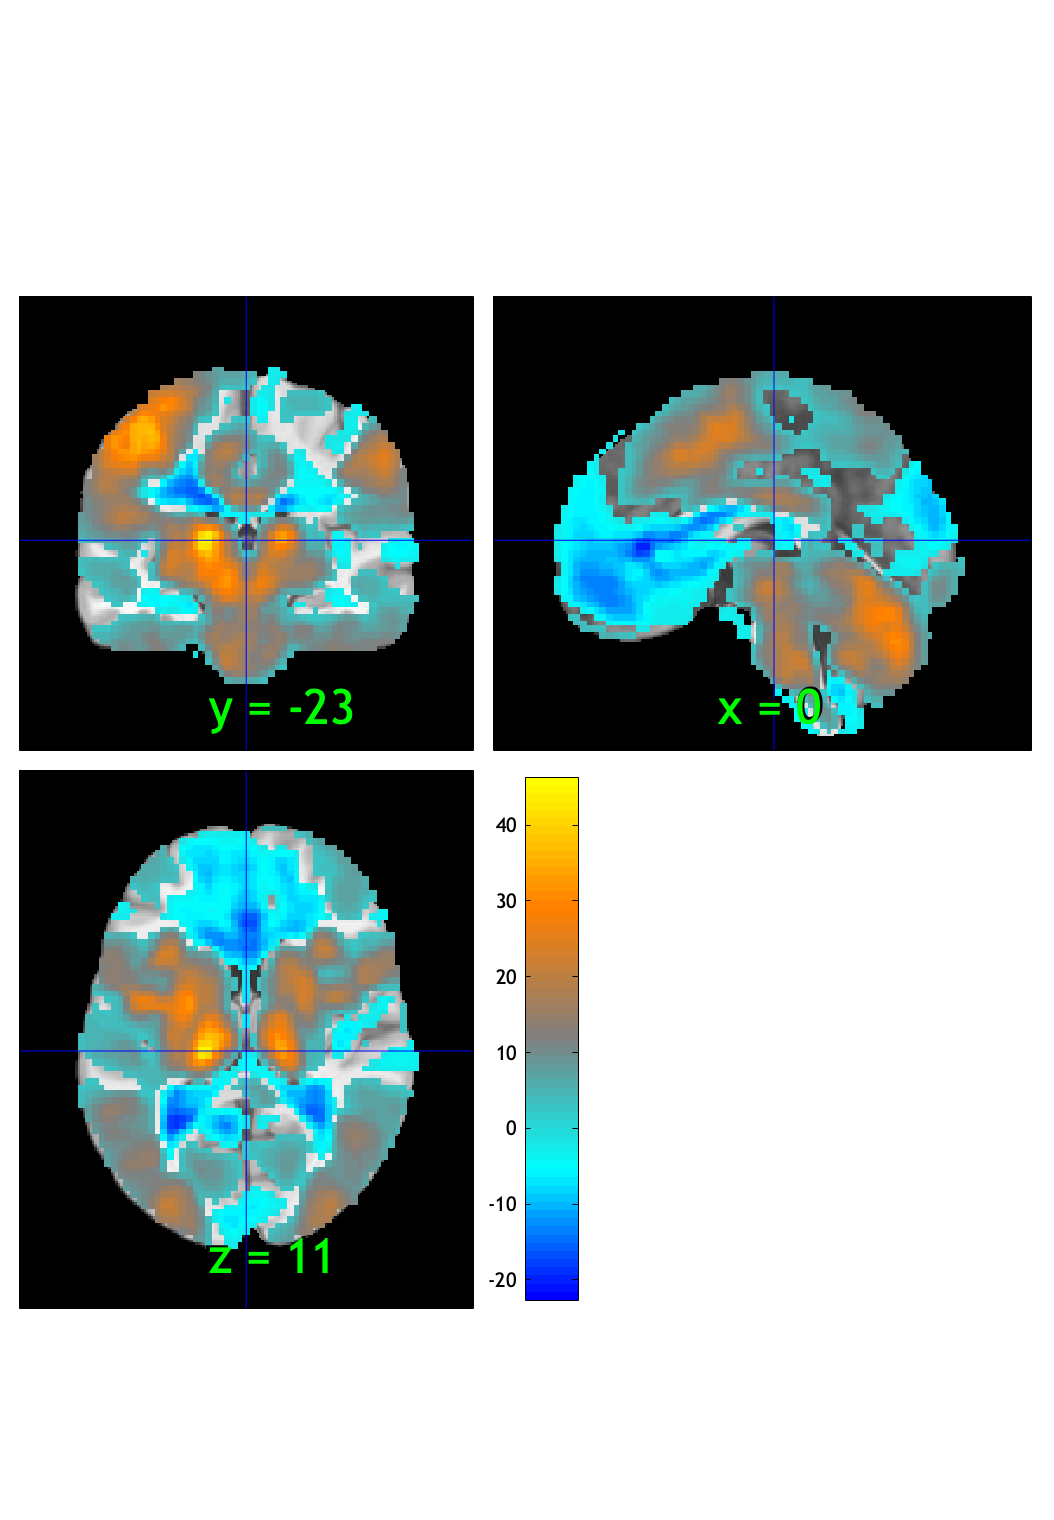

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:42:40 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0419
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 94
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimmotor_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000734

Image   1
 17 contig. clusters, sizes   1 to 73057
Positive effect: 60160 voxels, min p-value: 0.00000000
Negative effect: 13134 voxels, min p-value: 0.00000000


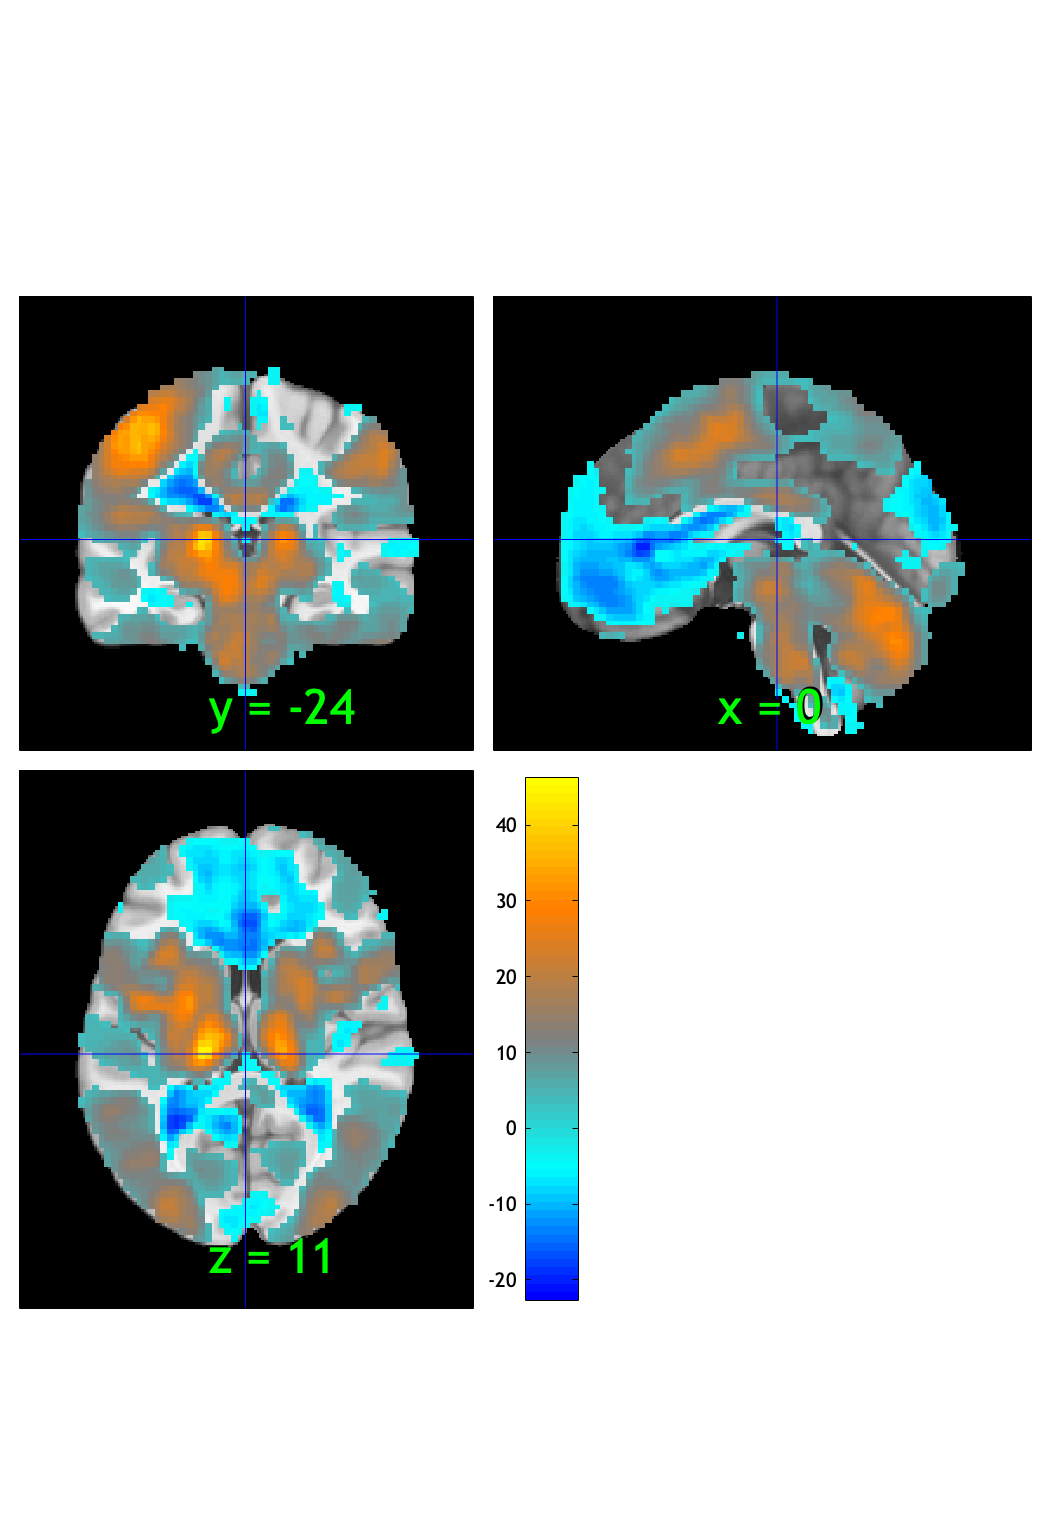

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:42:44 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 7.3361e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 94
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimmotor_fdr-001.nii



fdr_t0001 = threshold(t, .0001, 'fdr');

Image   1 FDR q < 0.000 threshold is 0.000069

Image   1
 22 contig. clusters, sizes   1 to 68262
Positive effect: 57213 voxels, min p-value: 0.00000000
Negative effect: 11356 voxels, min p-value: 0.00000000


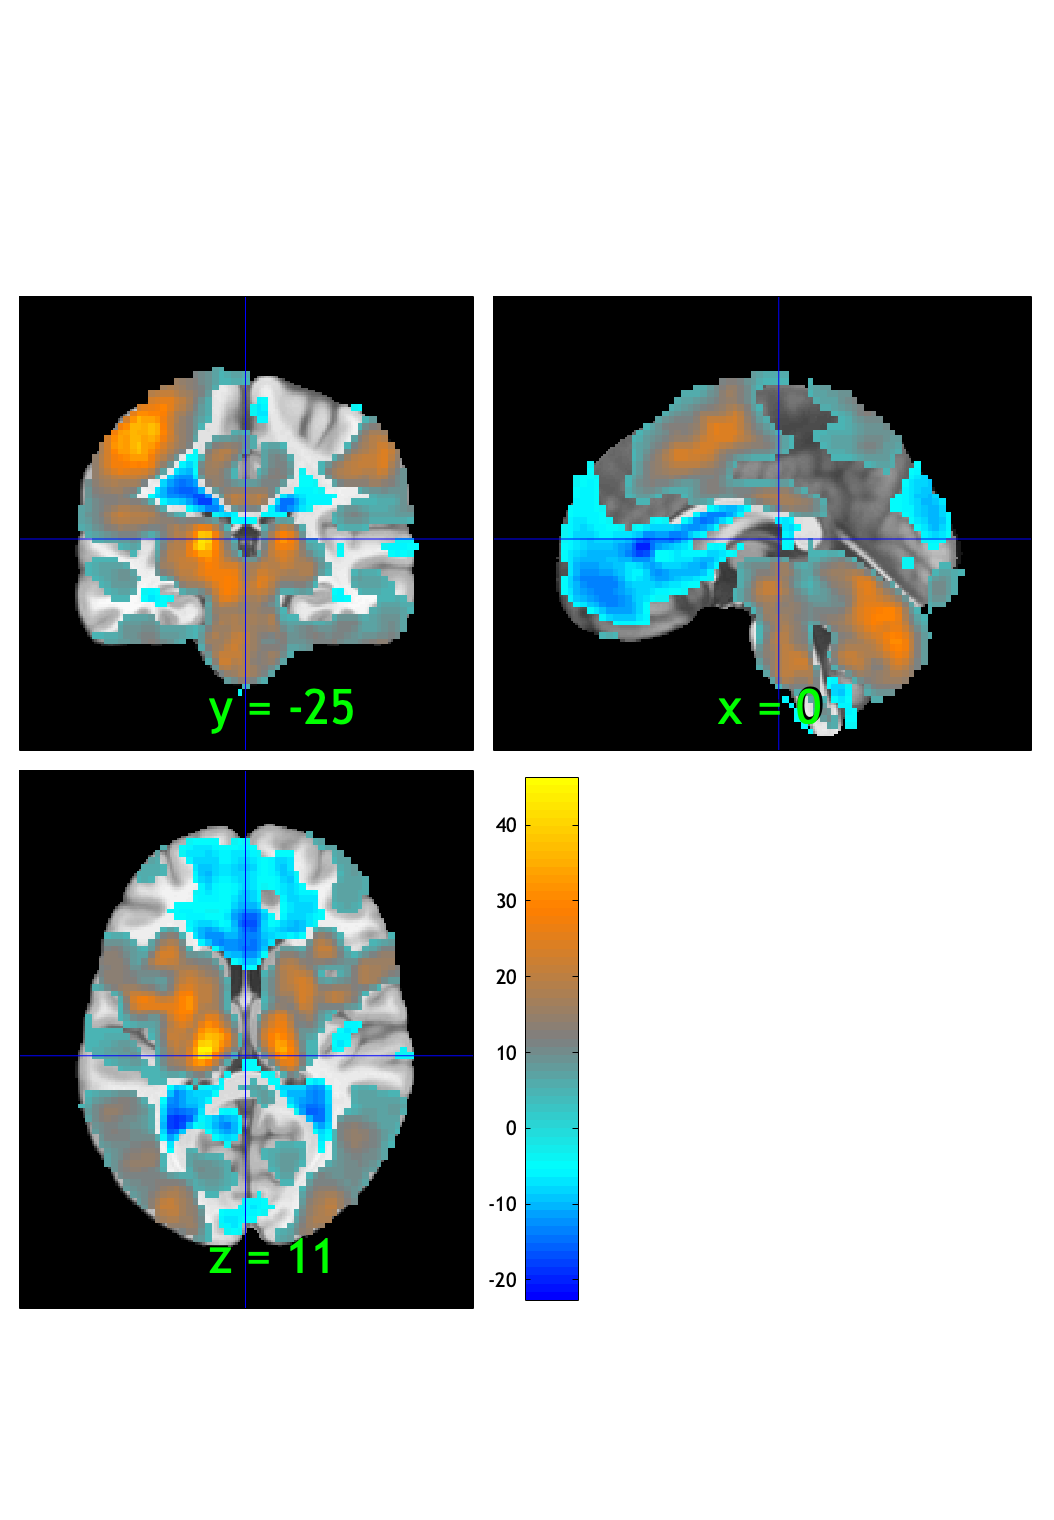

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              21:42:49 - 29/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


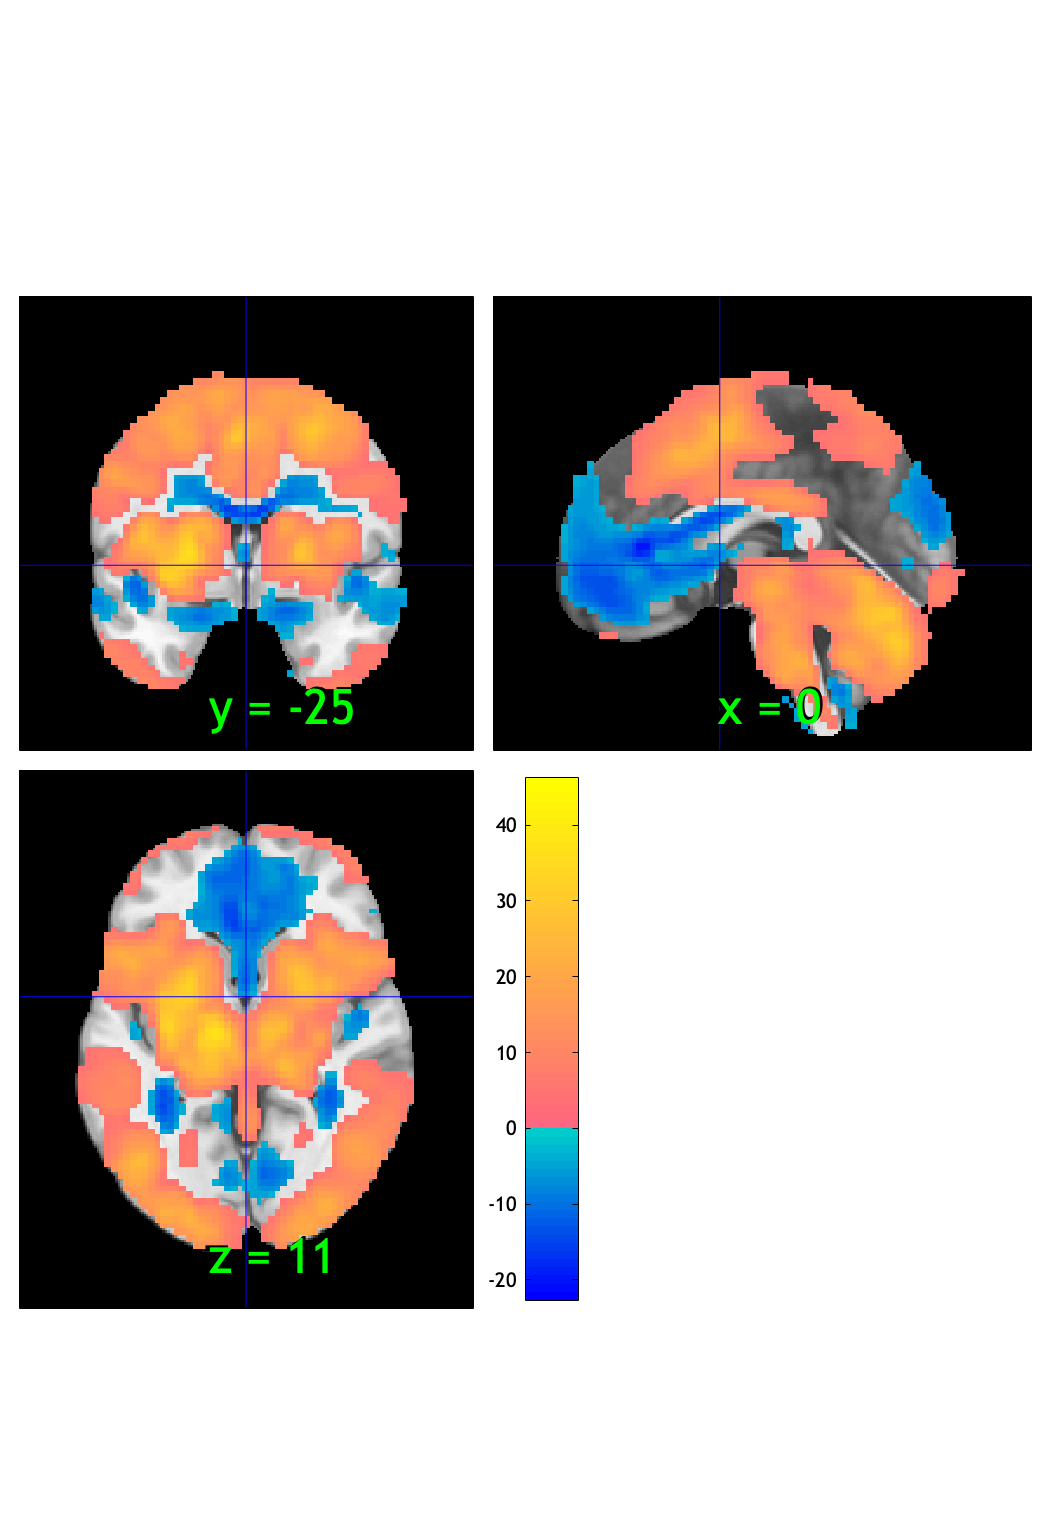

orthviews(fdr_t0001);

drawnow, snapnow;
fdr_t0001.dat = fdr_t0001.dat.*fdr_t0001.sig

fdr_t0001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 6.8665e-05
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 94
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t0001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-0001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel/model02-CESO_epoch-stimmotor_fdr-0001.nii


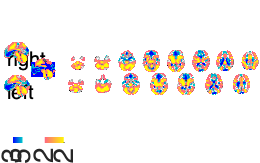

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1671 voxels displayed, 66898 not displayed on these slices
sagittal montage: 1652 voxels displayed, 66917 not displayed on these slices
sagittal montage: 1581 voxels displayed, 66988 not displayed on these slices
axial montage: 12416 voxels displayed, 56153 not displayed on these slices
axial montage: 13778 voxels displayed, 54791 not displayed on these slices




create_figure('montage'); axis off;
montage(fdr_t0001);

drawnow, snapnow;

#### Motor > baseline :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.33919     {'trait'     }     0.39406      {'movements'   }
    -0.33051     {'positive'  }     0.36553      {'execution'   }
    -0.33032     {'negative'  }     0.36355      {'hand'        }
    -0.31191     {'age'       }     0.33651      {'motor'       }
    -0.30291     {'personal'  }     0.33052      {'visual'      }
    -0.29727     {'depression'}     0.32076      {'finger'      }
    -0.29554     {'emotion'   }     0.29357      {'sensorimotor'}
    -0.29221     {'affect'    }     0.29006      {'action'      }
    -0.29144     {'person'    }     0.28973      {'hands'       }
    -0.28992     {'disorder'  }   

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

Motor** > baseline :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0160	-4.0741	0.0001	1.0000	***
Cog Wholebrain	0.0290	12.1713	0.0000	1.0000	***
Emo Wholebrain	-0.0109	-2.8895	0.0048	1.0000	**
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.015963     0.0039182     -4.074    9.5131e-05    -0.41366
    {'Cog Wholebrain' }      0.02902     0.0023829     12.178    2.2204e-15      1.2365
    {'Emo Wholebrain' }    -0.010883     0.0037659    -2.8899      0.004765    -0.29342



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [17.0007 18.0007 19.0007]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.011631      0.003573    -3.2553     0.0015655    -0.33052
    {'Cog Wholebrain' }     0.026268     0.0021801     12.049    2.2204e-15      1.2234
    {'Emo Wholebrain' }    -0.013058       0.00347    -3.7629    0.00028905    -0.38207



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [20.0007 21.0007 22.0007]


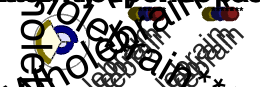

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')